# Lab 7: Event Slection Otimization & Jackknife 

**Megan Miyasaki **

Partner: Kuan Lee

For this lab, we will again work with the Higgs Classification data that we worked with in Lab 5, and apply whay we learned from the past two Labs 5 and 6, and use them to help us with this double Lab of 7 and 8. As a recall, for lab 5 we worked with  training datasets from one of the two pT-range folders. In each folder, there are 2 files, each containing 100k jets. The signal dataset is labeled as “higgs” and the background dataset is labeled as “qcd.” Between me and my lab partener we took two different sets of Higgs Classification data, I worked with the lowPT sample points 250-500, and analyzed:

- Do all features provide discrimination power between signal and background?

- Are there correlations among these features?

- Compute expected discovery sensitivity by normalizing each sample appropriately.

- Develop a plan to optimize the discovery sensitivity by applying selections to these features.

Lab 6, was a signal injection test, sadly we could not work with the 'real world' data, and therefore we built ur own background and injected our own signal strengths into the background data we made. 

For this Lab, Lab 7 we will be doing Jackknife test to hunt for very subtle effects. we will: 

- Identify a concern

- Split the data into two based on the concern 

- Analyze the data set separatly and difference. 

- A statistically significatn difference mean you have a problem, no differene means you can check off the worry. 

The first things we will do is make a stacked histogram plot for the feature variable mass, remember mass:

**‘mass’ ~ m**

The Invariant mass; if the two photons originated from a decaying Higgs boson, their invariant mass can be identified with the mass of the decaying Higgs boson; that is, a Higgs mass of 126GeV


$$\begin{array}{l}
E^2 =p^2 +m^2 ;E\;\textrm{is}\;\textrm{the}\;\textrm{energy}\;\textrm{of}\;\textrm{the}\;\textrm{particle},p\;\textrm{is}\;\textrm{the}\;\textrm{momentum}\ldotp \textrm{We}\;\textrm{can}\;\textrm{then}\;\textrm{rearrange}\;\textrm{the}\;\textrm{equation}\;\textrm{to}\;\\
m^2 =E^2 -p^2 
\end{array}$$


*I wil downlaod the data to read and analyze with the code below and create a stacked histogram of the variable mass: *

clear;close all;clc;

% downloading and importing the data for problem 1:

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


signal=h5read("higgs_100000_pt_250_500.h5", '/higgs_100000_pt_250_500');
h5disp("qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


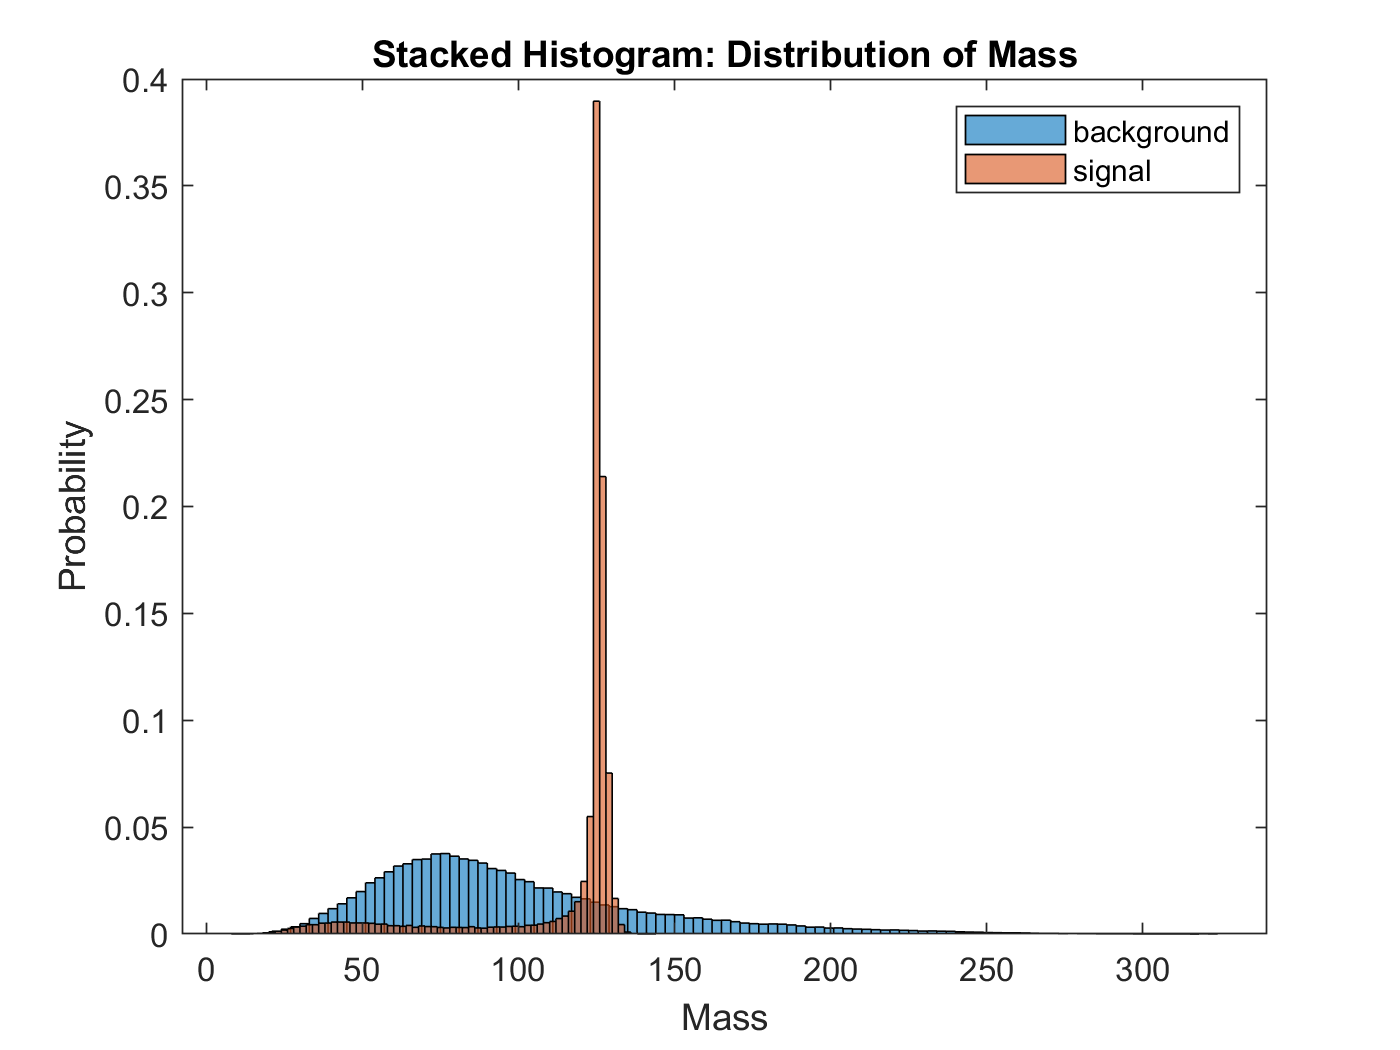

background=h5read("qcd_100000_pt_250_500.h5", '/qcd_100000_pt_250_500');

%mass comparison 
mass=background(4,:);
masss=signal(4,:);

h1=histogram(mass,'Normalization','probability');
hold on
h2=histogram(masss,'Normalization','probability');
legend('background','signal')
title('Stacked Histogram: Distribution of Mass')
ylabel('Probability')
xlabel('Mass')
hold off

From this graph we see that background as a Poisson distribtuion with a slight tail to the right, and the signal to be a sharp exponential growth. 

From past labs we know that the probability density function for the given values x and $\lambda$ is:


$$f\left(x|\lambda \right)=\frac{\lambda^x }{x!}e^{-\lambda } ;x=0,1,2\ldotp \ldotp \ldotp ,\infty$$


Since I do not know much about my background data aside from the fact it looks a bit poisson distributed, I will use the fitdist functionin matlab to learn more. 

poisson=fitdist(mass','Poisson'); % gives me the mean of the background. 

I will now find how significant the signal is away from the background mean, by treating the distribution as a gaussian or normal distribution, since the signal should be centered around the true mass of the higgs boson, 125.34GeV, we will find the sigma that value is away from the mean of our background to find the significance. 

The code is finding the x-value for where we are 5 sigma away from the mean:


$$\int_{125}^0 \mathrm{pdf}\left(x\right)\mathrm{dx}=?$$


prob=1-cdf(poisson,125) %125 is the true mass of a higgs boson

prob = 0.0034

sigma=icdf('Normal',1-prob,0,1)

sigma = 2.7050

With this I see that the probability background of a poisson distribution is 0.0034 and the significance away the signal is 2.7 sigma away from the mean of the poisson background. 

The last thing I want to do is compare the number of $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }};N_{\mathrm{Higgs}} =100\;\&\;N_{\mathrm{QCD}} =20000$ to the number of my findings 

N_mass=20000; %background, qcd
N_masss=100; %higgs, signal
M=N_masss/sqrt(N_mass);

We find the $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$ = 3.16e+02, which is not equivalent to our probability or sigma values that we found earlier, so we should need to try and identify a good mass cut to optimize the expected significance. Upon further review from my ta, these values should be equivalent and close to one, making cuts would only impromve the expected significance, once the background and uncessary signal is cut. 

## Mass Cuts to Optimize the expected significance

I want to find cuts that increase the SNR by remvinb the background (mostly) to do that, I will remove all background data that does contain the majority of the signal data. 

*When I look at the graph, the mass of the Higgs Boson is 125, so I would want to cut the background of values lower than 120 and higher than 130 because they are close to the true mass. *

%cut 1: 120<mass<130
mass(mass<=120)=[]; %less than
mass(mass>130)=[]; %greater than
N_mass=length(mass); %background, qcd

masss(masss<=120)=[]; %less than
masss(masss>130)=[]; %greater than
N_masss=length(masss);%higgs, signal

M=N_masss/sqrt(N_mass)

M = 1.0834e+03

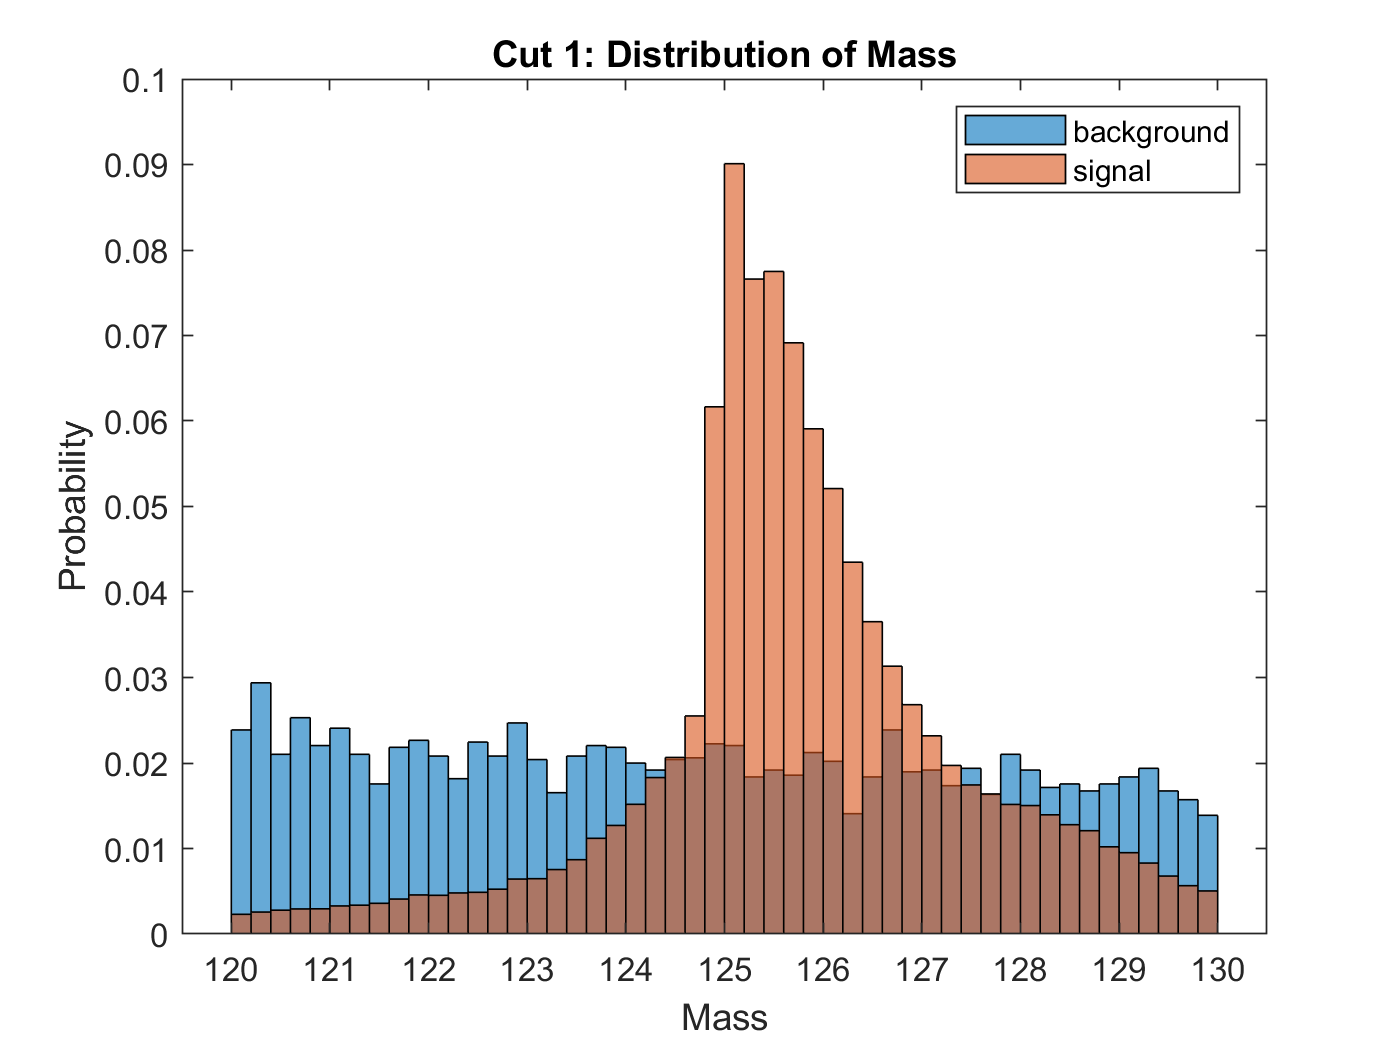

h3=histogram(mass,50,'Normalization','probability');
hold on
h4=histogram(masss,50,'Normalization','probability');
legend('background','signal')
title('Cut 1: Distribution of Mass')
ylabel('Probability')
xlabel('Mass')
hold off

From the plot we see that the background still having a slight effect and we can cut even more from both, and the new expected significance by taking the ratio of $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$ = 1.428. I will now see what happens if I cut even more data away. 

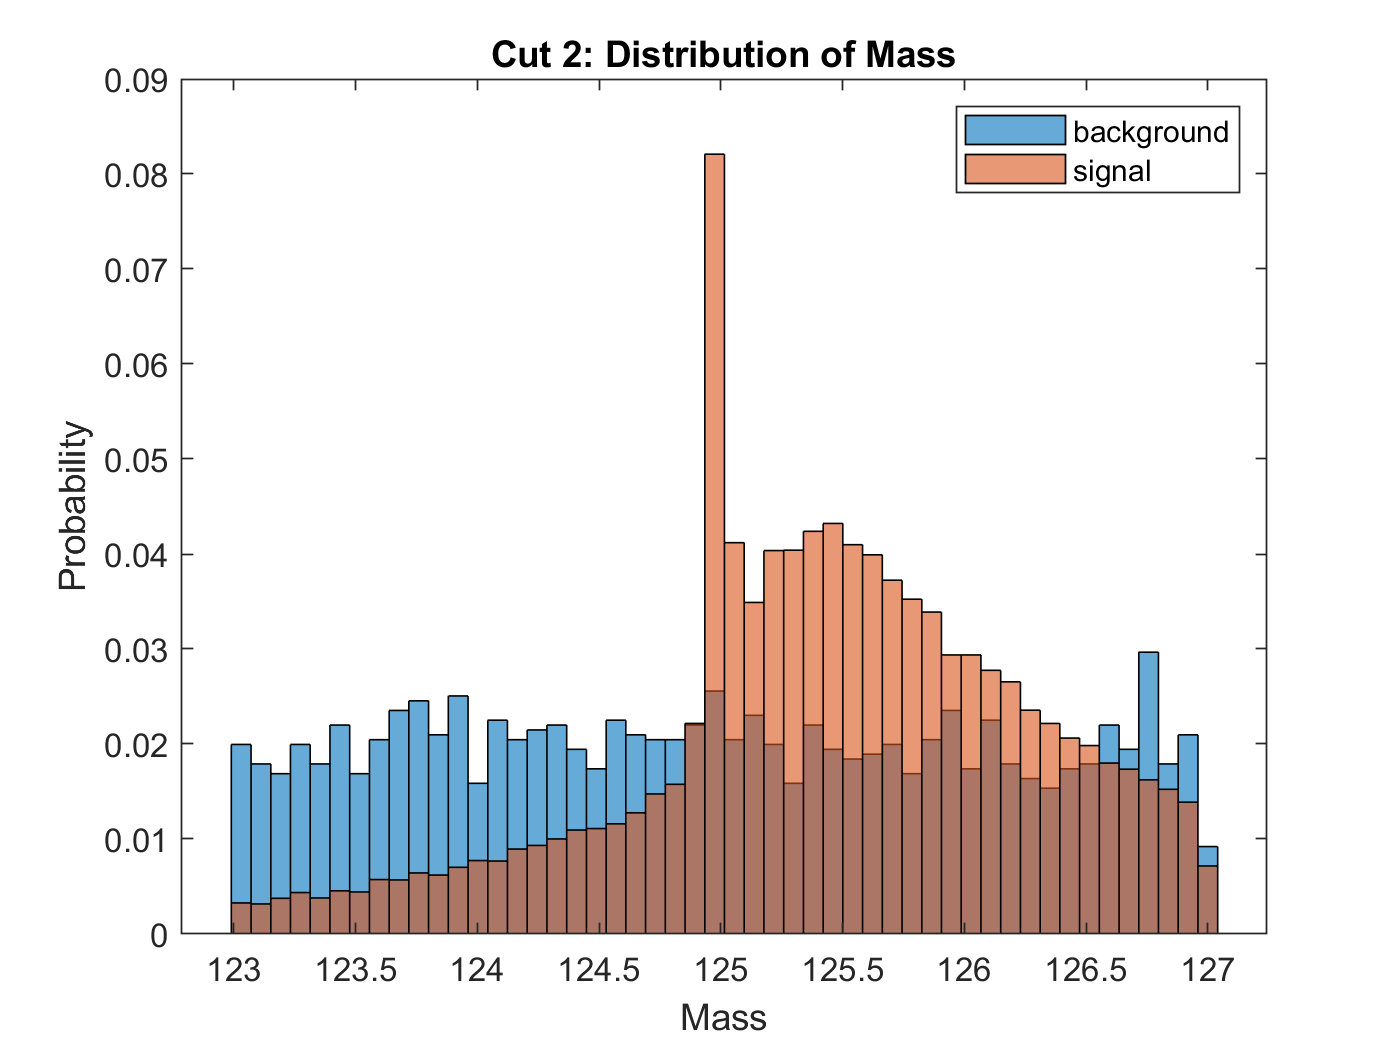

%cut 2: 123<mass<127
mass(mass<=123)=[]; %less than
mass(mass>127)=[]; %greater than
N_mass=length(mass); %background, qcd

masss(masss<=123)=[]; %less than
masss(masss>127)=[]; %greater than
N_masss=length(masss);%higgs, signal

M=N_masss/sqrt(N_mass);
h3=histogram(mass,50,'Normalization','probability');
hold on
h4=histogram(masss,50,'Normalization','probability');
legend('background','signal')
title('Cut 2: Distribution of Mass')
ylabel('Probability')
xlabel('Mass')
hold off

Again, from the plot we see that the background is still effecting the true signal of 125, and the new expected significance by taking the ratio of $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$ = 2.26. I will now do one more cut to see if it will affect the expected significance. 

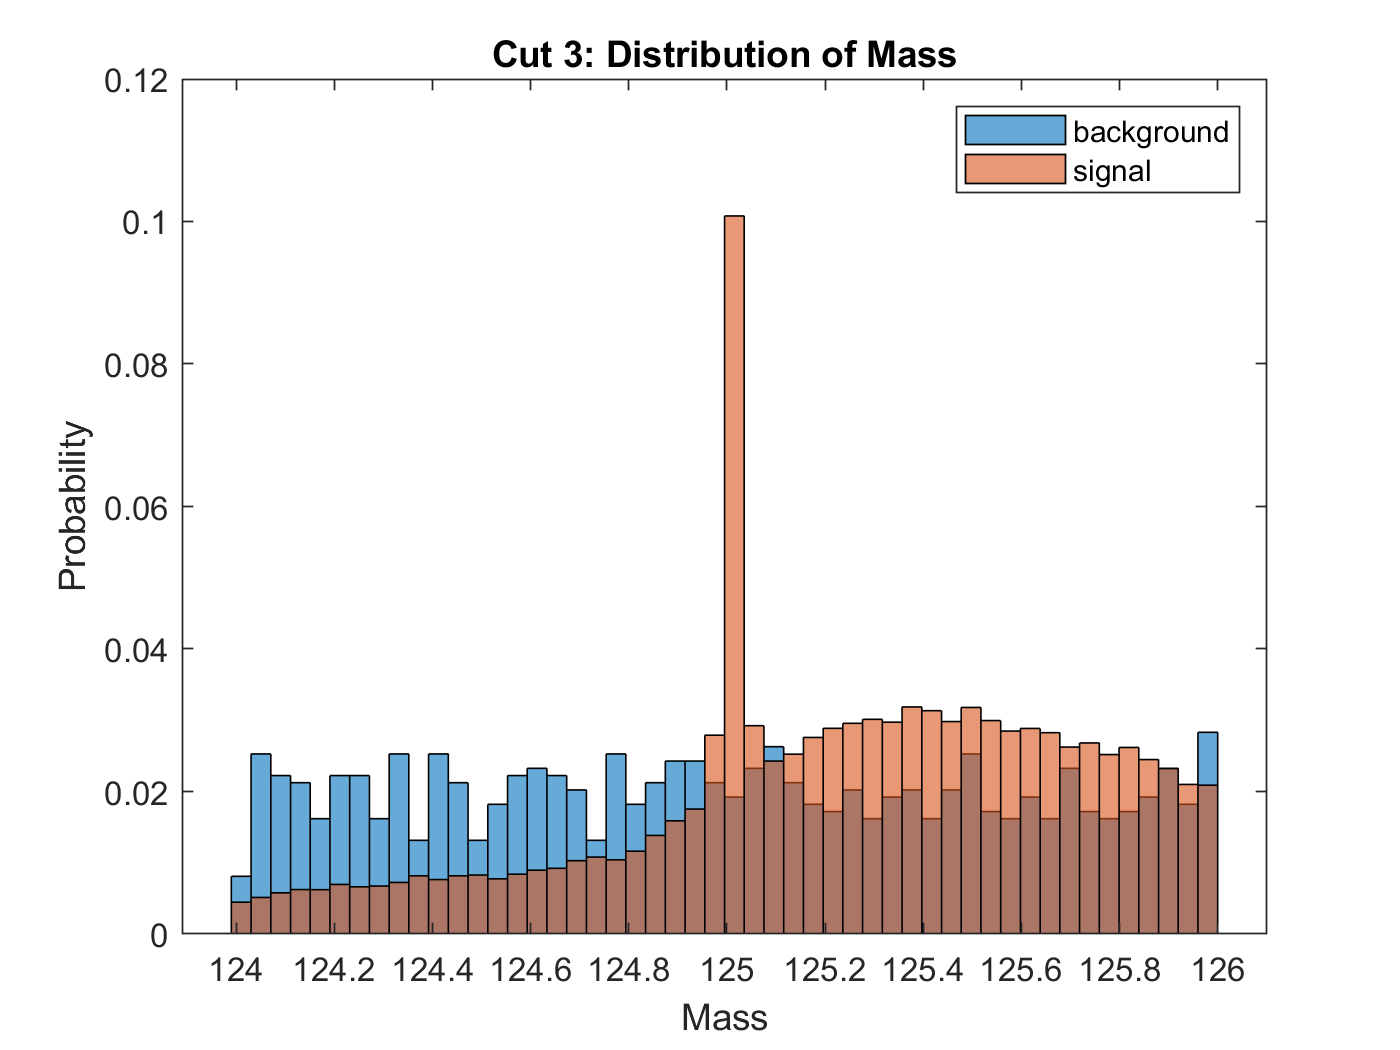

%cut 3: 124<mass<126
mass(mass<=124)=[]; %less than
mass(mass>126)=[]; %greater than
N_mass=length(mass); %background, qcd

masss(masss<=124)=[]; %less than
masss(masss>126)=[]; %greater than
N_masss=length(masss);%higgs, signal

M=N_masss/sqrt(N_mass);
h3=histogram(mass,50,'Normalization','probability');
hold on
h4=histogram(masss,50,'Normalization','probability');
legend('background','signal')
title('Cut 3: Distribution of Mass')
ylabel('Probability')
xlabel('Mass')
hold off

Again, from the plot we see that the background is hidden behind the signal, and the new expected significance by taking the ratio of $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{QCD}} }}$ = 3.18. I will now do one more cut to see if it will affect the expected significance. 

## Stacked Histogram Plots for rest of the features

Here I will make plot of the rest of the features and see if another feature is discriminative as the mass feature, in general we are seeing if they have an equal or better signifcance after feature cuts. As a reminder the rest of the features are: 

**‘pt’ ~ **$p_t$

The Higgs boson transverse-momentum. Transverse plane, is the xy plane with phi as the angel of measurement. It is calculated from transversal energy, delivered on calorimeters with units GeV. pT,1 and pT,2, the transverse momenta of the two sujet merged in the final step of clustering. 


$$\sqrt{p_x^2 +p_y^2 };P_x^2 =\mathrm{momentum}\;\mathrm{in}\;x\;\mathrm{direction},P_y^2 =\mathrm{momentum}\;\mathrm{in}\;y\;\mathrm{direction}\;$$


**‘eta’ ~ η**

The pseudorapidity  is a commonly used spatial coordinate describing the angle of a particle relative to the beam axis. It is defined as. where is the angle between the particle three-momentum and the positive direction of the beam axis.


$$\eta =-\mathrm{ln}\left\lbrack \left(\mathrm{tan}\left(\frac{\theta }{2}\right)\right)\right\rbrack$$


**‘phi’ ~ϕ**

The azimuthal angle, which is used for the jet azimuthal angle correlations in the production of Higgs boson pair of two jets at hardon colliders. 


$${\mathrm{cos}}^{-1} \left(\frac{x}{r}\right)$$


**Subjettiness ~ **$\tau_N$

N-subjettiness variables are defend by clustering the constituents of a jet with the exclusive ktalgorithem and requiring that N subjets are found.  Given N subjet axes in a fat jet, N – subjettiness, $\tau_N$is given by 


$$\tau_N =\frac{1}{d_0 }\sum_k P_{T,k} \mathrm{min}\left\lbrace \left\lbrack \Delta R_{1,k} ,\Delta R_{2,k} ,\ldotp \ldotp \ldotp ,\Delta R_{N,k} \right\rbrack \right\rbrace$$


- $\Delta R_{N,k}$ Is the angular separation between constituent k and candidate subjet N 

- $d_o$  is a normalization factor given by: $d_0 =\sum_k P_{T,k} R_0 \;\mathrm{so}\;0\le \tau_N \le 1$

- $R_0 =0\ldotp 8$for AK8 clustering. 

Also, ‘t1’,’t2’,’t3’ equate to $\tau_{1,2,3}$, ‘t21’ and ‘t32’ are the Subjettiness ratios 

**‘ee2’ ~e2 & ‘ee3’ ~e3**

The 2-point ECF ratio or the 3-point ECF ratio, with ECF = energy correlation function, therefore ECF ration is the ratio of energy correlation functions. The energy correlation functions are defined with the motivation that (N+1) – point correlators are sensitive to N-prong subtractors. 


$$\begin{array}{l}
e_2 =\sum_{1\le i<j<\mathrm{nJ}} Z_i \;Z_j \;R_{\mathrm{ij}} \;R_{\mathrm{ik}\;} \;\;,\;e_3 \;=\sum_{1\le i<j<k\le \mathrm{nJ}} Z_i \;Z_j \;Z_k \;R_{\mathrm{ij}} \;R_{\mathrm{ik}\;} R_{\mathrm{jk}} ,;\\
\mathrm{with}\;Z_i \equiv \frac{p_{\mathrm{Ti}} }{\sum_{j\epsilon \mathrm{jet}} p_{\mathrm{Tj}} },R_{\mathrm{ij}} =\sqrt{{\left(\phi_i -\phi_j \right)}^2 +{\left(y_i -y_j \right)}^2 }\;;\phi_i =\mathrm{azumthal}\;\mathrm{angle}\;
\end{array}$$


**‘d2’ ~ D2**

Defined as a double ratio of ECFs, 3-to-2 – point ECF ratio: 


$$D_2 =\frac{e_3 }{{\left.{\left(e\right.}_2 \right)}^3 }$$


**‘angularity’ a3**

Jet mass (M), width, eccentricity, planar flow and angularity are measured for jets reconstructed using the anti-kt algorithm with distance parameters R=0.6 and 1.0, with transverse momentum pT>300  GeV and pseudorapidity |η|<2.

The formula of angularity is:


$$\begin{array}{l}
\tau_a =\frac{1}{M}\sum_i E_i \sin^a \theta_i \;{\left\lbrack 1-\cos \left(\theta_i \right)\right\rbrack }^{1-a} \\
\textrm{where}\;M\;\textrm{is}\;\textrm{the}\;\textrm{jet}\;\textrm{mass}\;\textrm{and}\;a\;\textrm{is}\;\textrm{the}\;\textrm{parameter}\;\textrm{that}\;\textrm{can}\;\textrm{be}\;\textrm{chosen}\;\textrm{to}\;\\
\textrm{emphasis}\;\textrm{radiation}\;\textrm{near}\;\textrm{the}\;\textrm{edges}\;\left(a<0\right)\;\textrm{or}\;\textrm{core}\left(a>0\right)\ldotp 
\end{array}$$


**‘KtDeltaR ~ kt** **Δ****R**

ΔR of two subjects within the large-R jet with the kt splitting scale, this variable is obtained by reclustering the constituents of a jet with kt algorithm, which usually clusters last the harder constituents, and  then taking the kt distance measure between the two subject at the final stage of the recombination procedure. As well, ΔR the corresponding angular separation 

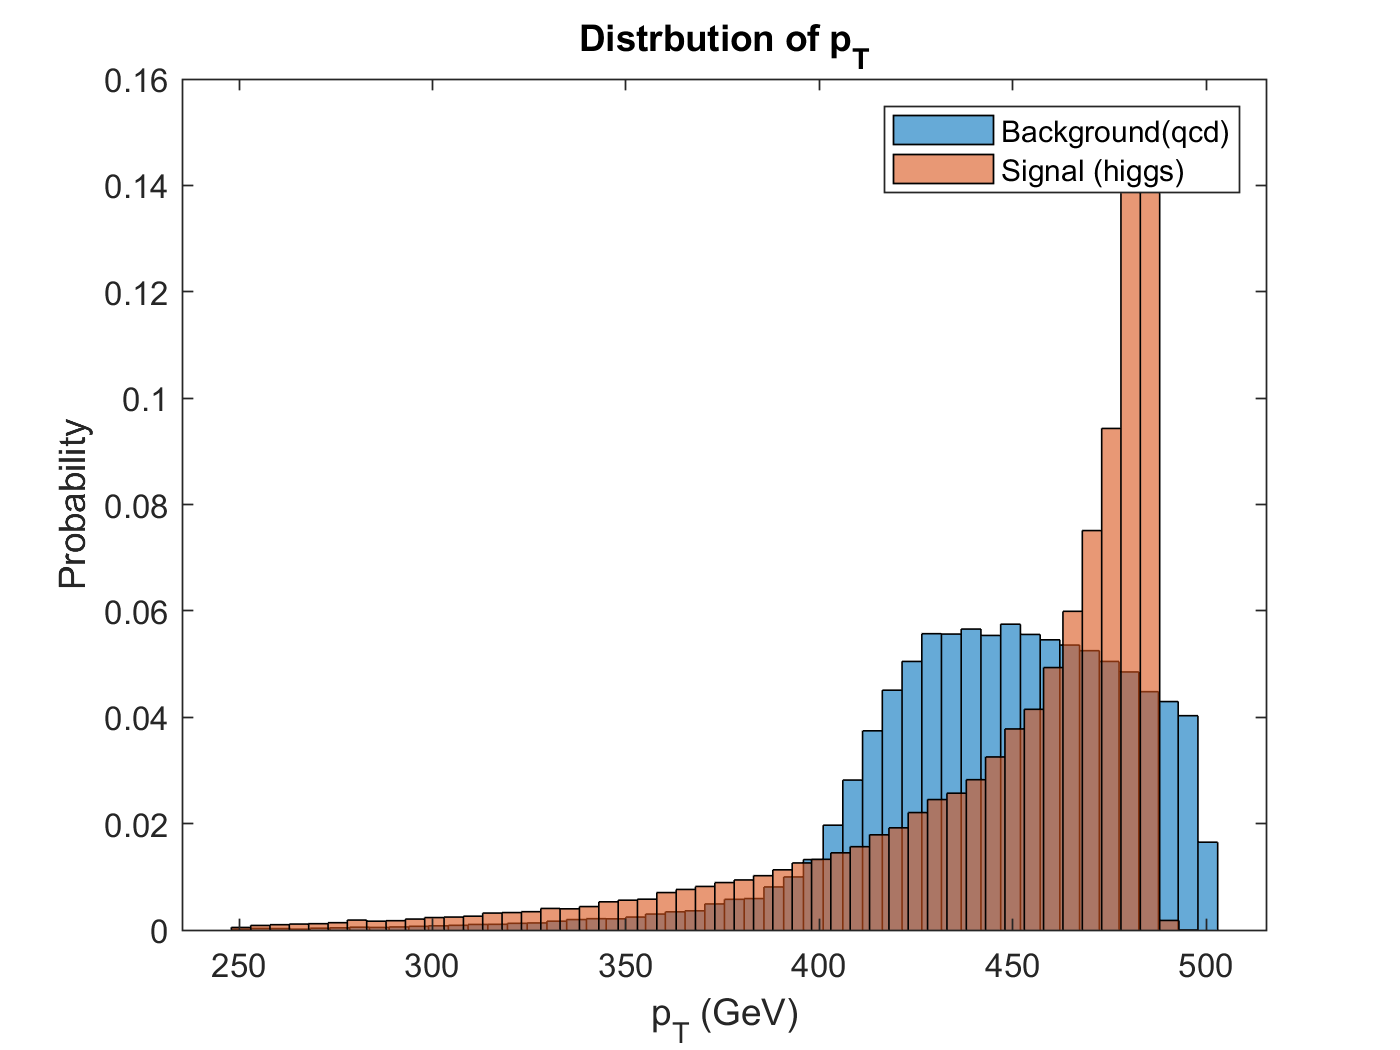

% pt, between higgs and qcd
pt=background(1,:);
pts=signal(1,:);
histogram(pt,50,'Normalization','probability')
hold on 
histogram(pts,50,'Normalization','probability')
legend('Background(qcd)','Signal (higgs)')
title('Distrbution of p_{T}')
ylabel('Probability')
xlabel('p_{T} (GeV)')
hold off

From this plot we see that they are not the same shape nor do the share the same mean, so the background could be effecting the signal. Therefore this might be a good graph to make cuts to optimize the expected significance. The signal seems to spike around 475, I will make cuts around 474 and 476 to both background and signal to optimize the expected significance. 

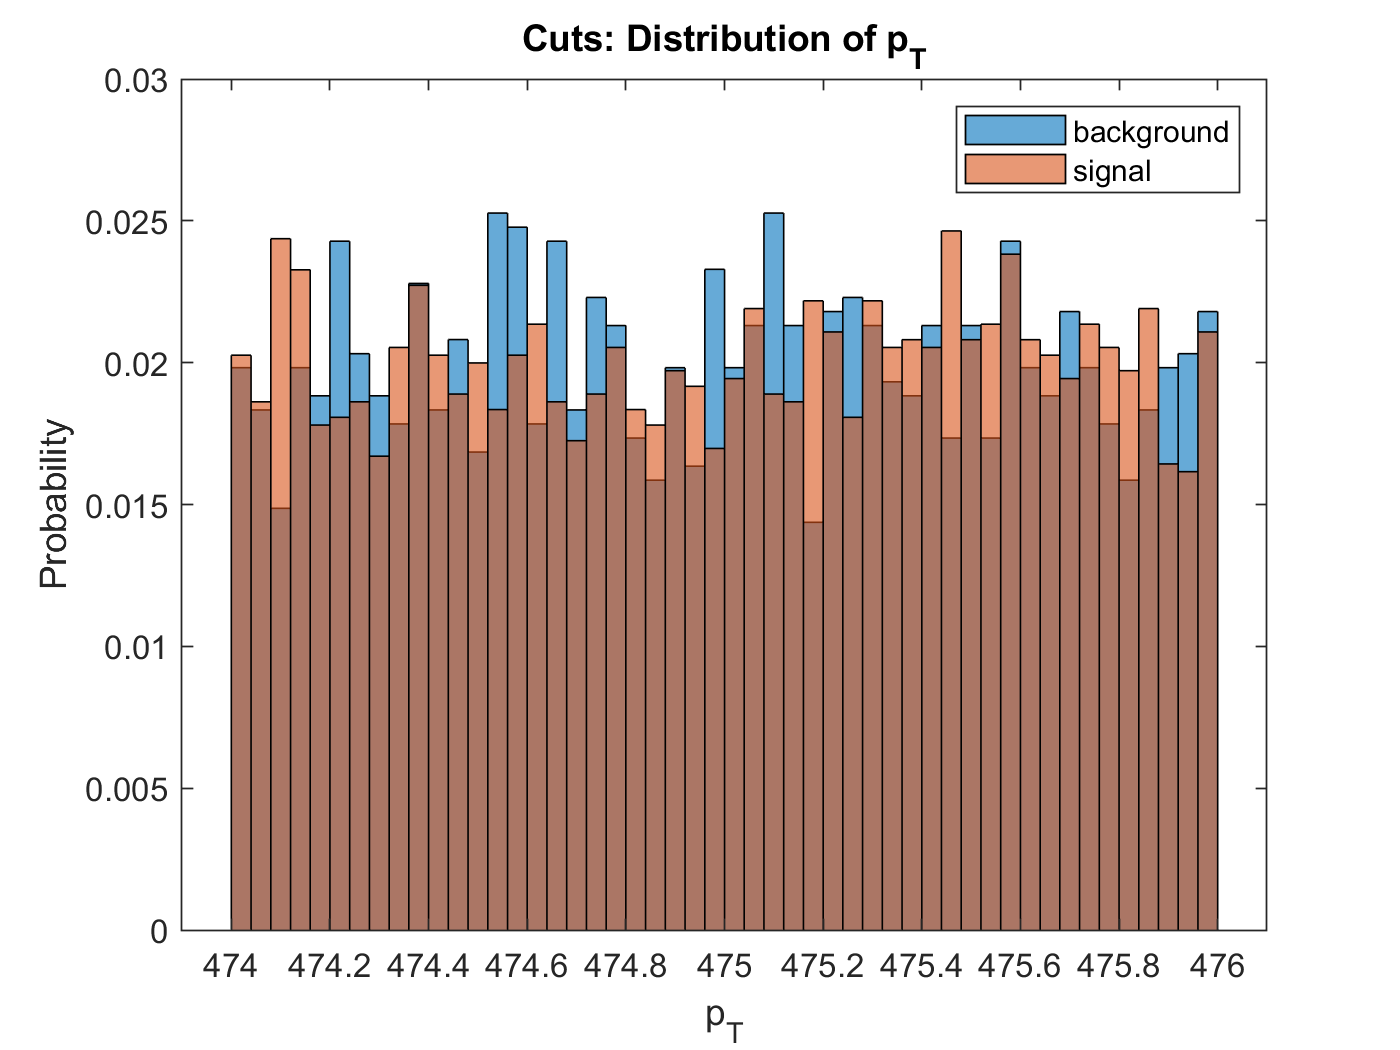

%cut: 124<pt<126
pt(pt<=474)=[]; %less than
pt(pt>476)=[]; %greater than
N_pt=length(pt); %background, qcd

pts(pts<=474)=[]; %less than
pts(pts>476)=[]; %greater than
N_pts=length(pts);%higgs, signal

M=N_pts/sqrt(N_pt);
h3=histogram(pt,50,'Normalization','probability');
hold on
h4=histogram(pts,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of p_{T}')
ylabel('Probability')
xlabel('p_{T}')
hold off

The plot of the cut, is similar enough were I would not perform anymore cuts to optimize the expected significance. 

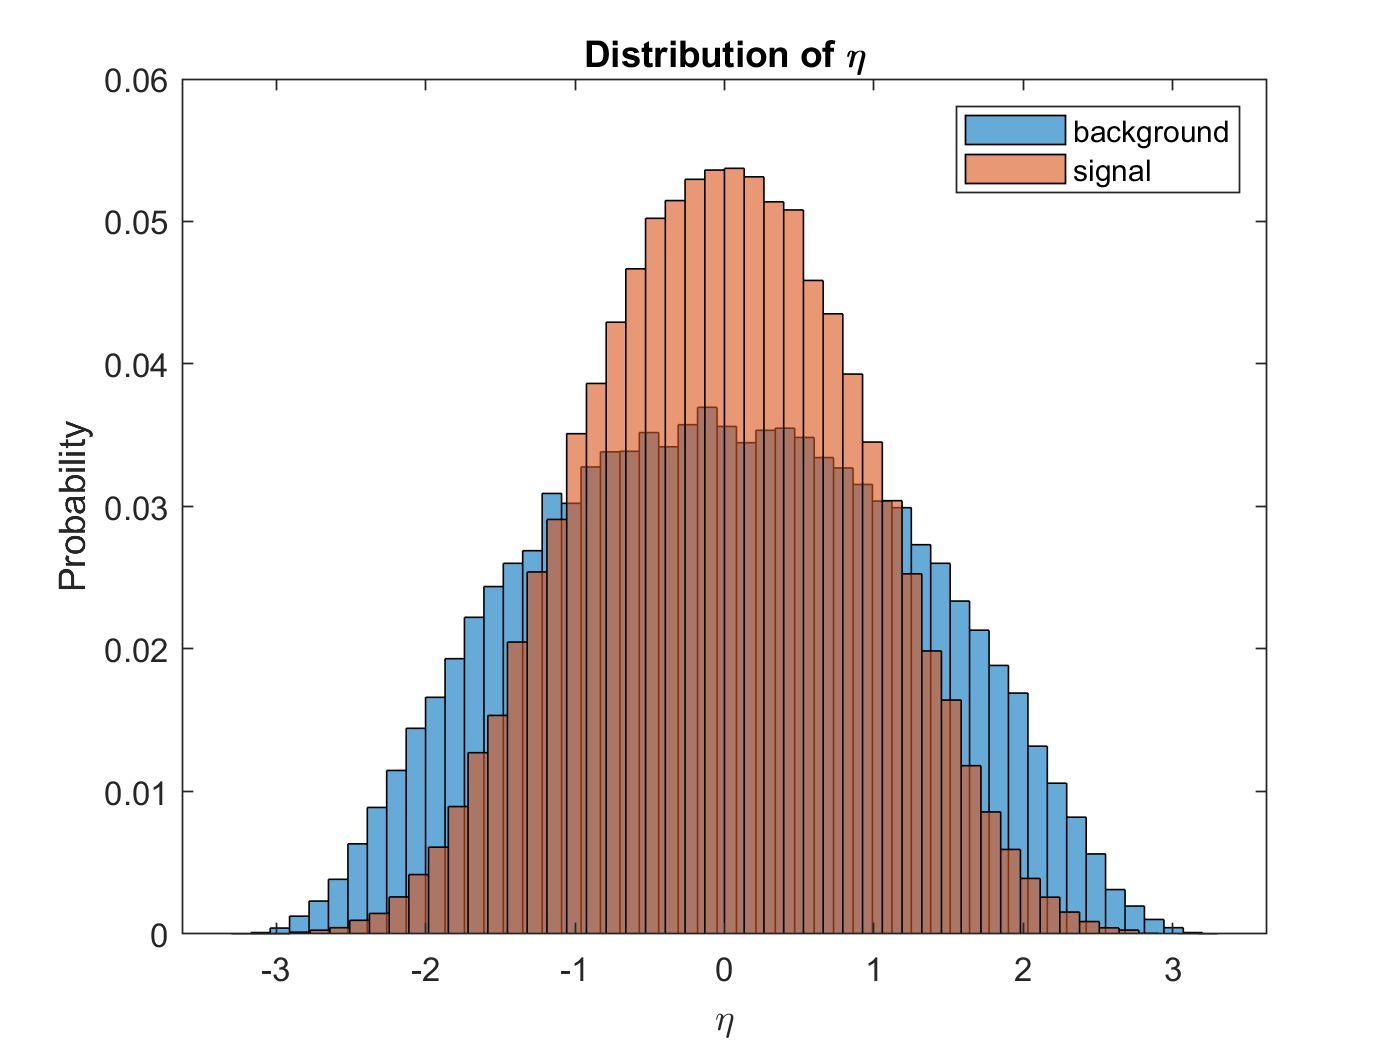

% plot eta of background and signal 
eta=background(2,:);
etas=signal(2,:);

histogram(eta,50,'Normalization','probability');
hold on
histogram(etas,50,'Normalization','probability');
legend('background','signal')
title('Distribution of \eta')
ylabel('Probability')
xlabel('\eta')
hold off

The eta plot seems to show that they have a similar shape as well as sharing the same mean to be around zero, making cuts to this graph may not be necessary. 

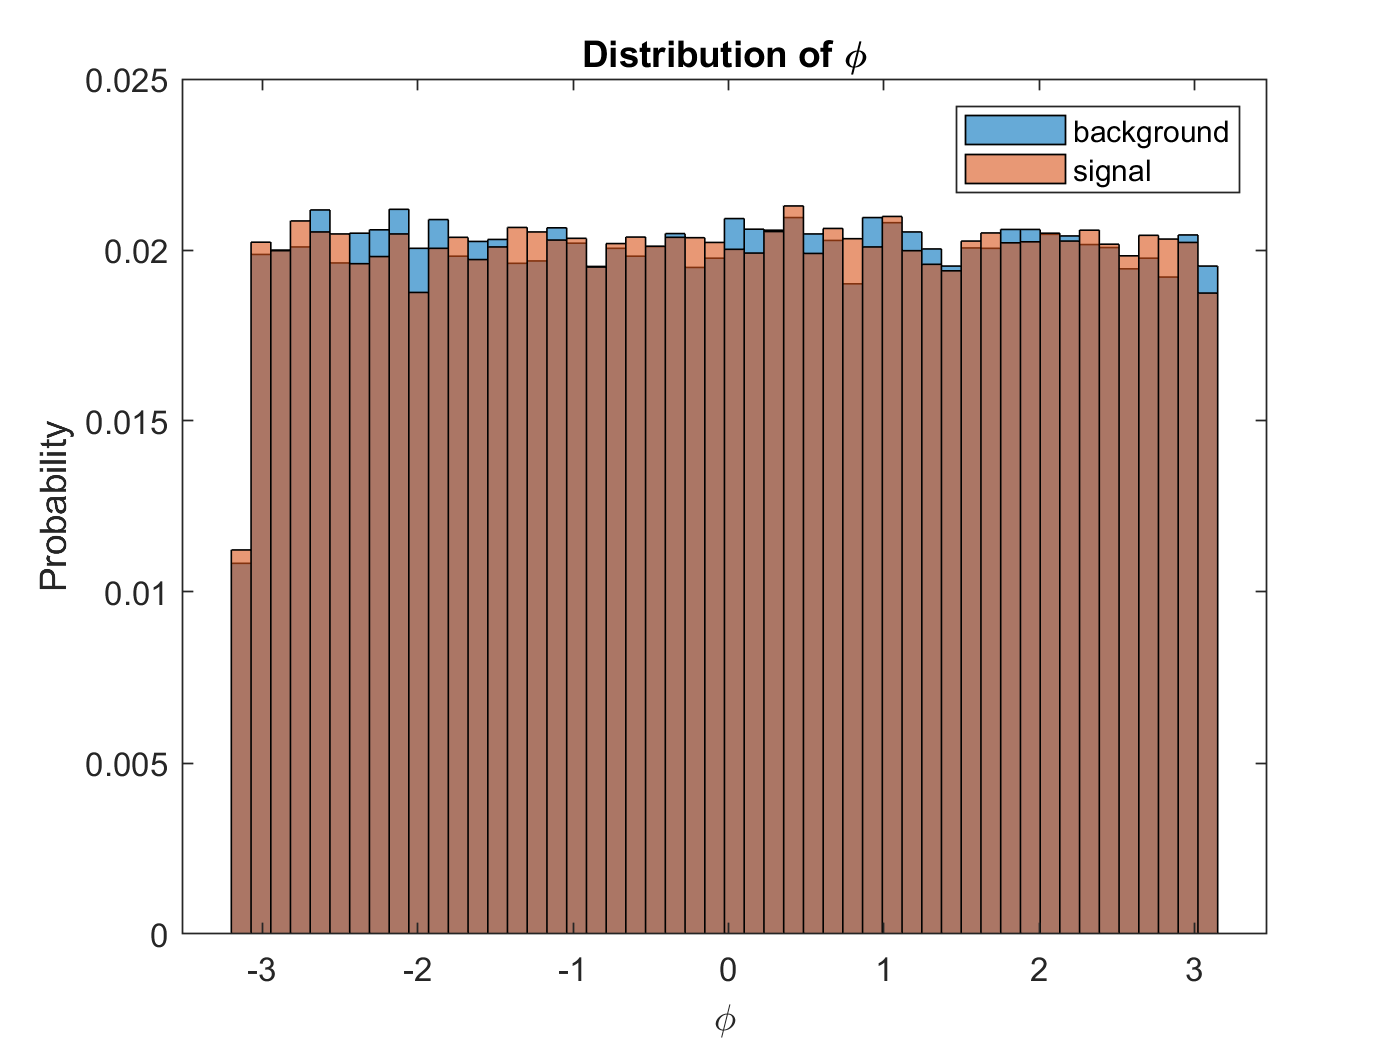

% Comparing the phi, 
phi=background(3,:);
phis=signal(3,:);

histogram(phi,50,'Normalization','probability')
hold on
histogram(phis,50,'Normalization','probability')
legend('background','signal')
title('Distribution of \phi')
ylabel('Probability')
xlabel('\phi')
hold off

 The plot for phi, shows that both the background and signal share a similar pattern and shape, as well as they are distributed evenly around zero. 

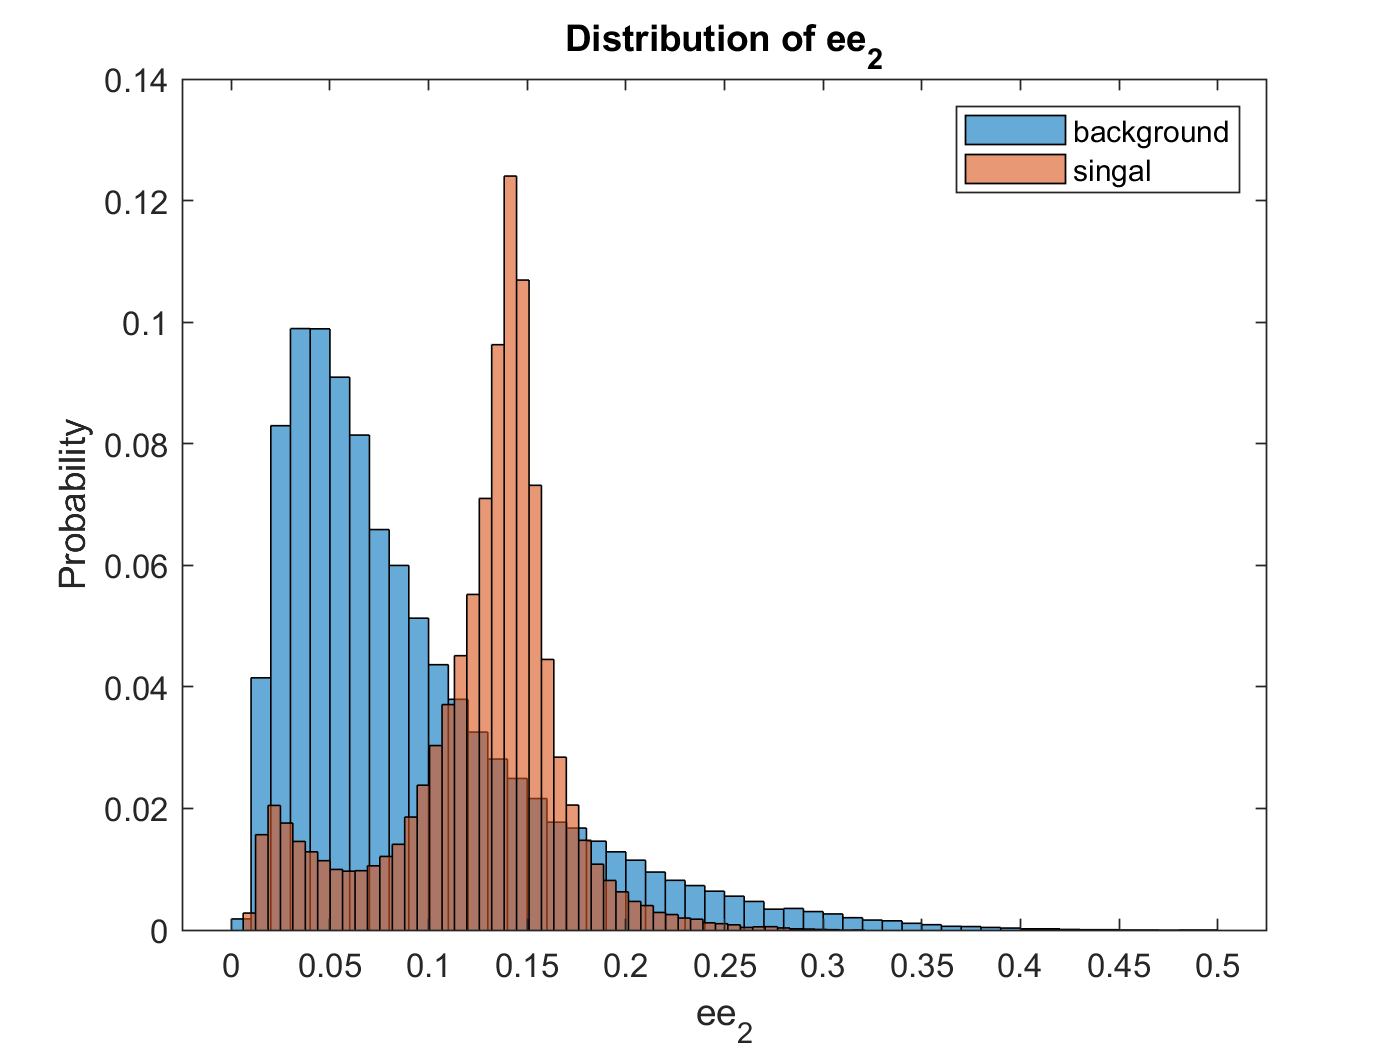

% comparing ee2 
ee2=background(5,:);
ee2s=signal(5,:);
histogram(ee2,50,'Normalization','probability')
hold on
histogram(ee2s,50,'Normalization','probability')
legend('background','singal')
title('Distribution of ee_{2}')
ylabel('Probability')
xlabel('ee_{2}')
hold off

The ee2 plot has such different shapes and mean, it is clear the background noise is effect the signal, doing cuts to optimize the expected significane will help alot. I would cut anything below 0.13 and above 0.16, effectively getting rid of alot of background while keeping a lot of my signal. 

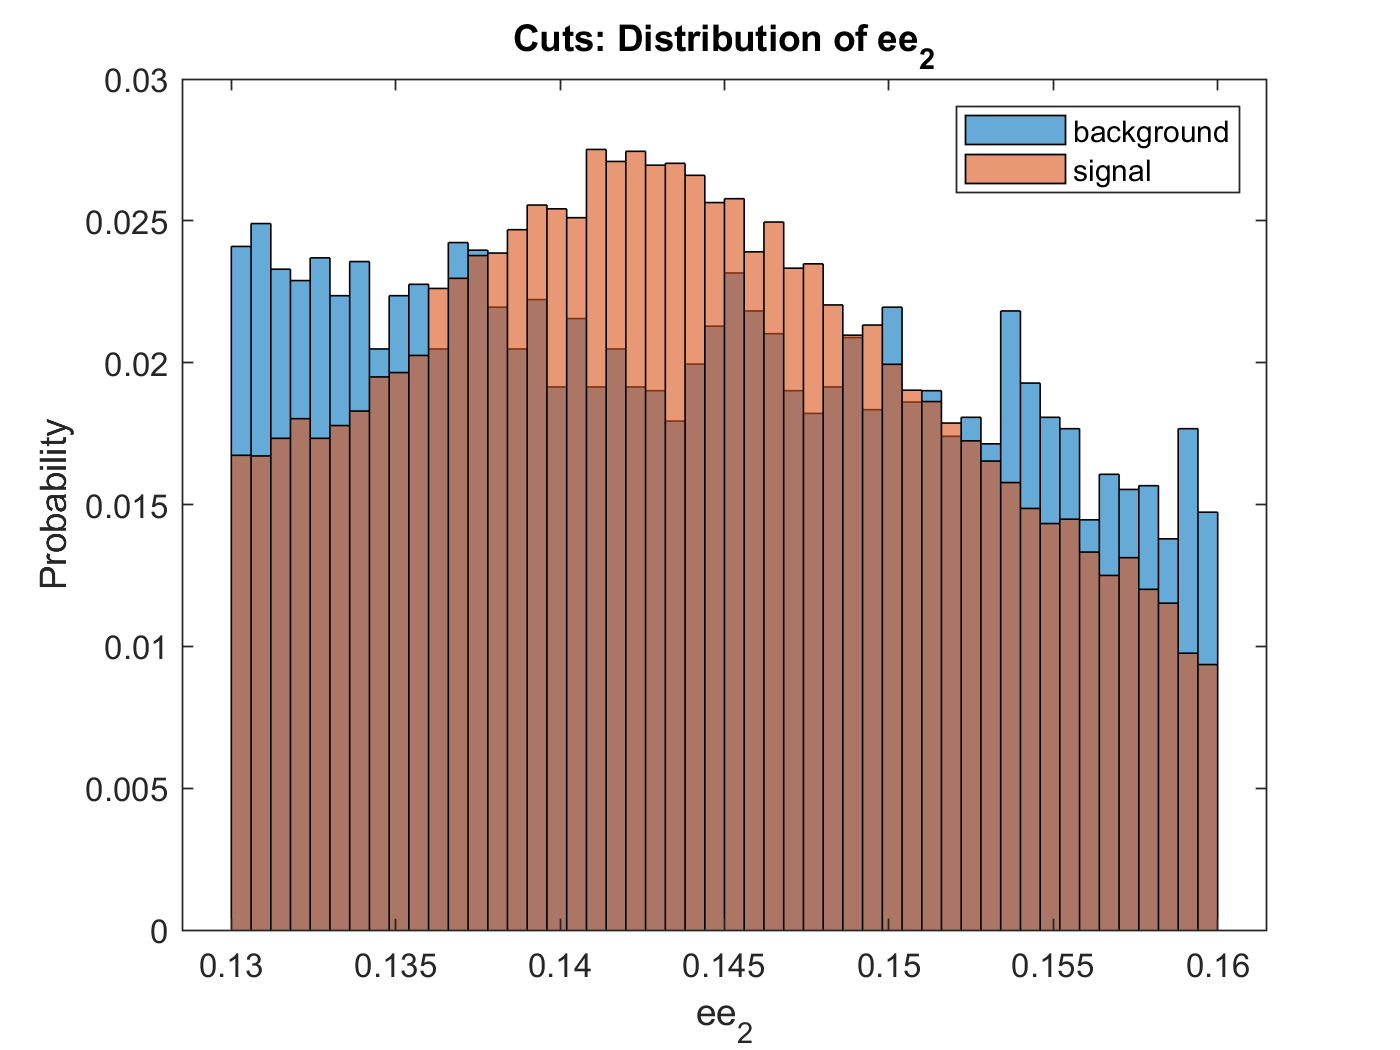

%cut: 0.13<pt<0.18
ee2(ee2<=0.13)=[]; %less than
ee2(ee2>0.16)=[]; %greater than
N_ee2=length(ee2); %background, qcd

ee2s(ee2s<=0.13)=[]; %less than
ee2s(ee2s>0.16)=[]; %greater than
N_ee2s=length(ee2s);%higgs, signal

M=N_ee2s/sqrt(N_ee2);
histogram(ee2,50,'Normalization','probability');
hold on
histogram(ee2s,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of ee_{2}')
ylabel('Probability')
xlabel('ee_{2}')
hold off

The plot of the cut, is similar enough were I would not perform anymore cuts to optimize the expected significance. 

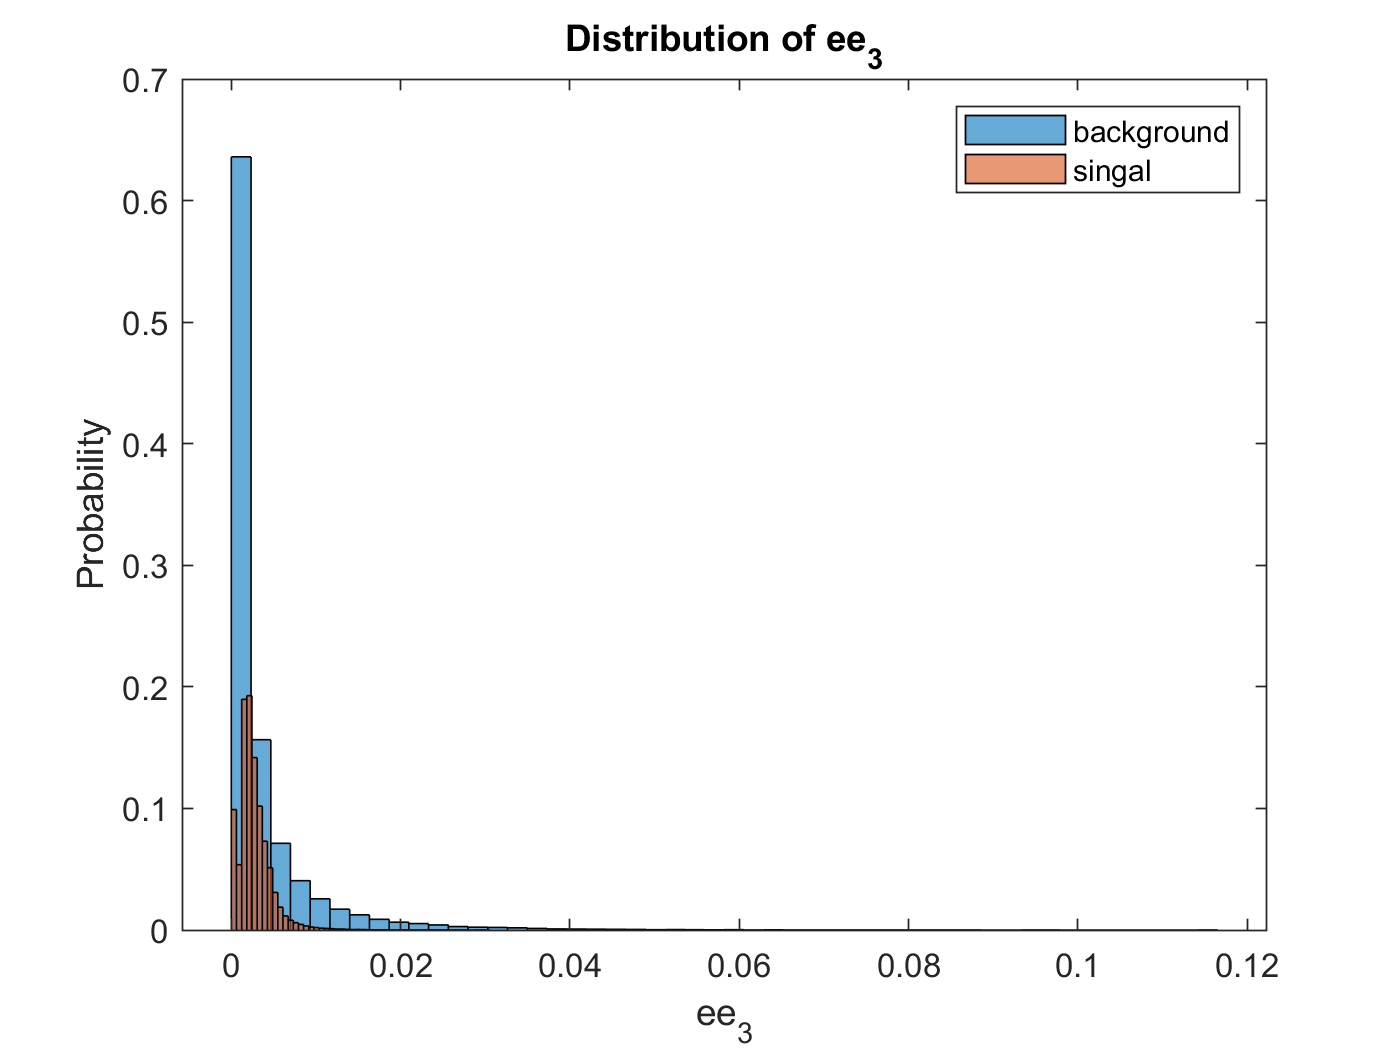

% comparing ee3 
ee3=background(6,:);
ee3s=signal(6,:);
histogram(ee3,50,'Normalization','probability')
hold on
histogram(ee3s,50,'Normalization','probability')
legend('background','singal')
title('Distribution of ee_{3}')
ylabel('Probability')
xlabel('ee_{3}')
hold off

The ee3 plot has the same shape and the spike share the same value as the background. I will not perform cuts to ee3. 

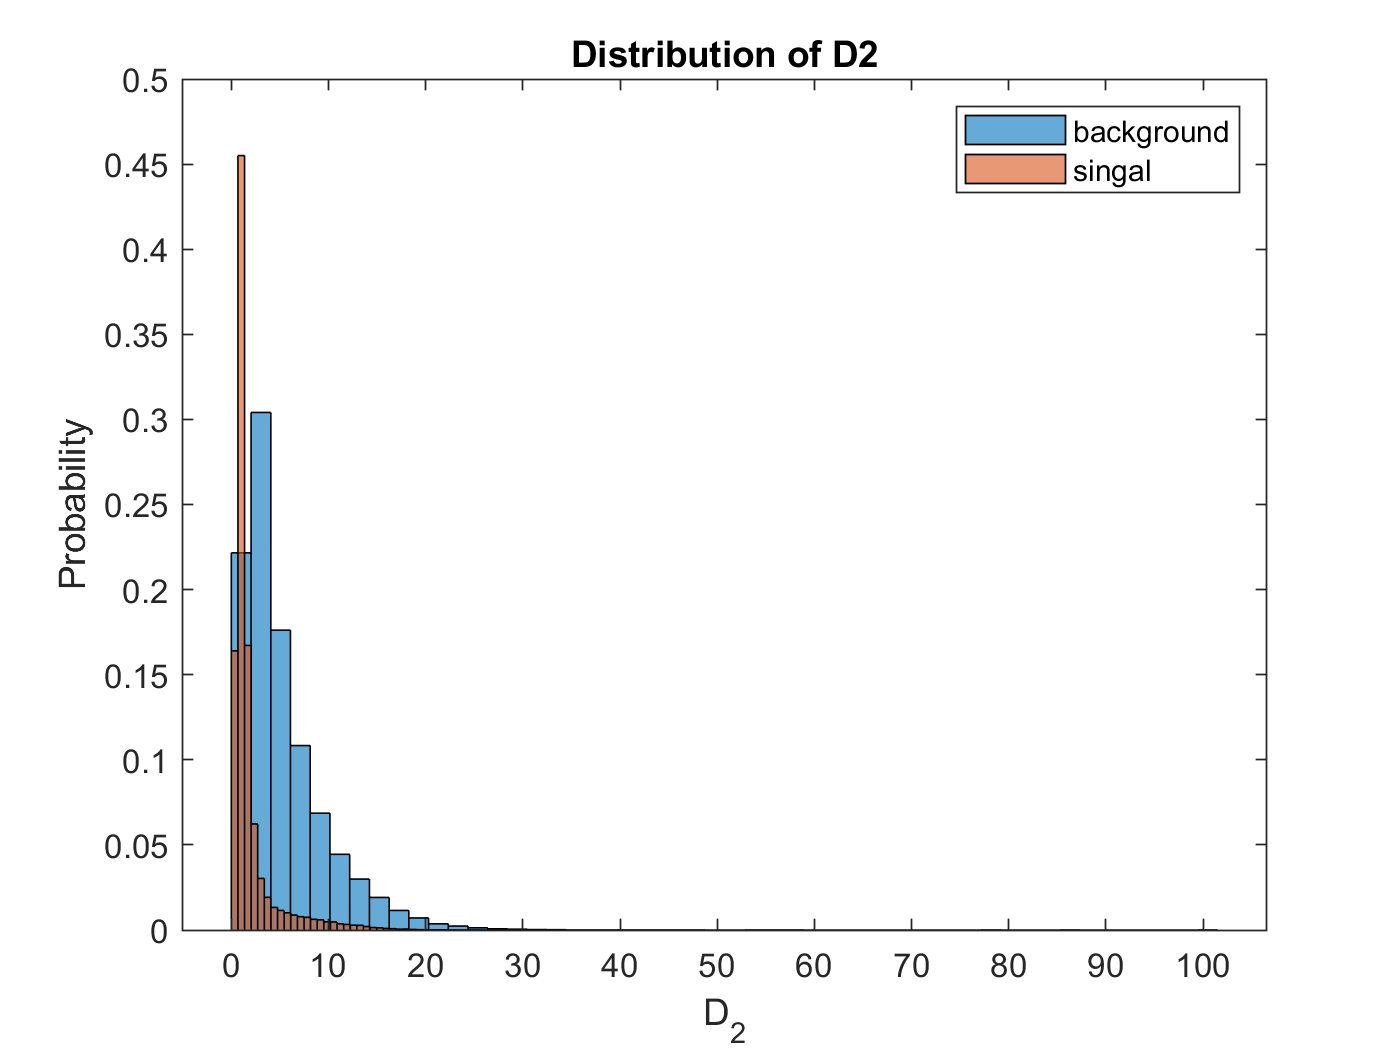

% comparing d2 background and signal 
d2=background(7,:);
d2s=signal(7,:);

histogram(d2,50,'Normalization','probability')
hold on
histogram(d2s,50,'Normalization','probability')
legend('background','singal')
title('Distribution of D2')
ylabel('Probability')
xlabel('D_{2}')
hold off

While D2 has the same type of exponential decay, tand they have the same area of the spike, I do not think the background is affecting the signal enough to want to perform cuts to optimize the expected significance. 

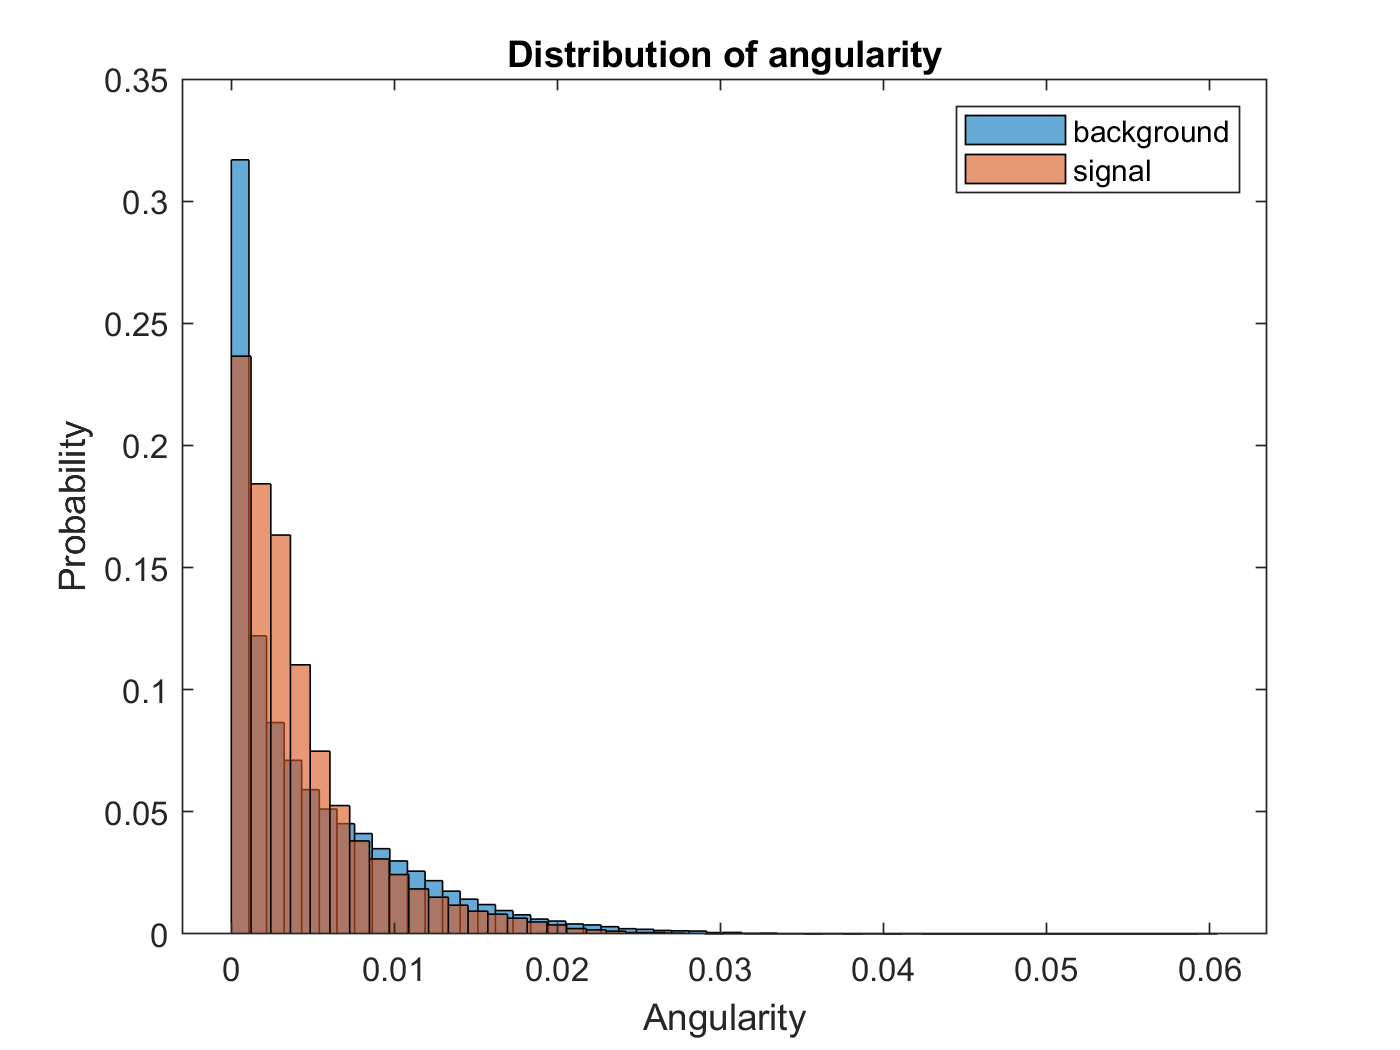

%angularity 
ang=background(8,:);
angs=signal(8,:);

histogram(ang,50,'Normalization','probability')
hold on
histogram(angs,50,'Normalization','probability')
legend('background','signal')
title('Distribution of angularity')
ylabel('Probability')
xlabel('Angularity')
hold off

Angularity plot seems to share the same shape of an exponential decay as well as the same placement of a spike, doing any cuts may be a trivial and will not effect the expected significane too much. 

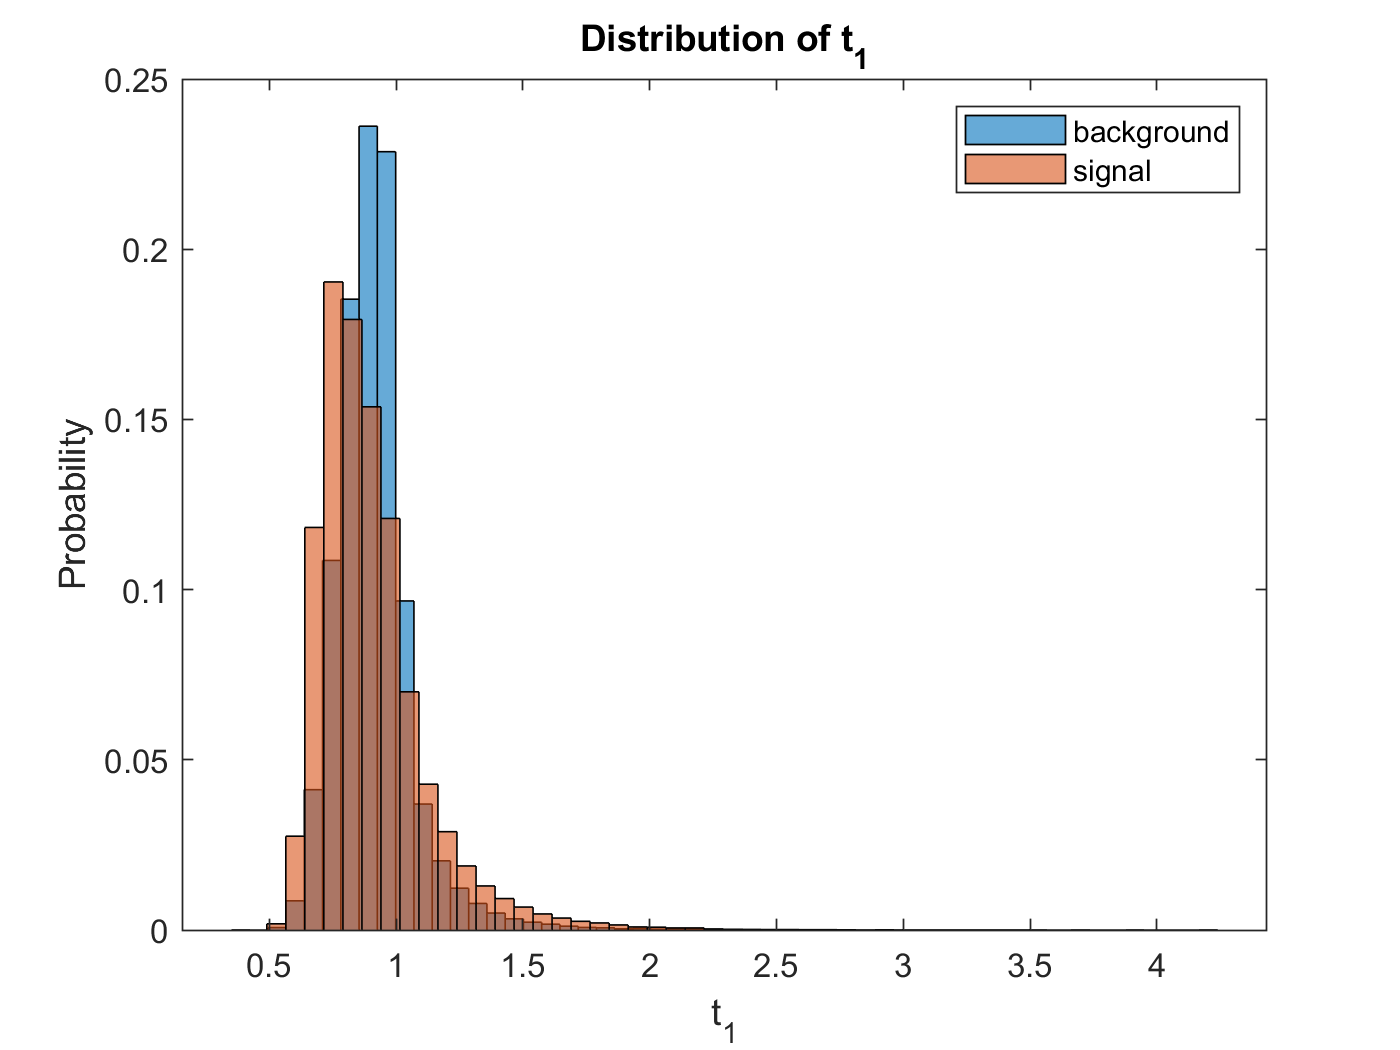

%plot t1
t1=background(9,:);
t1s=signal(9,:);

histogram(t1,50,'Normalization','probability')
hold on
histogram(t1s,50,'Normalization','probability')
legend('background','signal')
title('Distribution of t_{1}')
ylabel('Probability')
xlabel('t_{1}')
hold off

The plot is similar enough were I would not perform cuts to optimize the expected significance. 

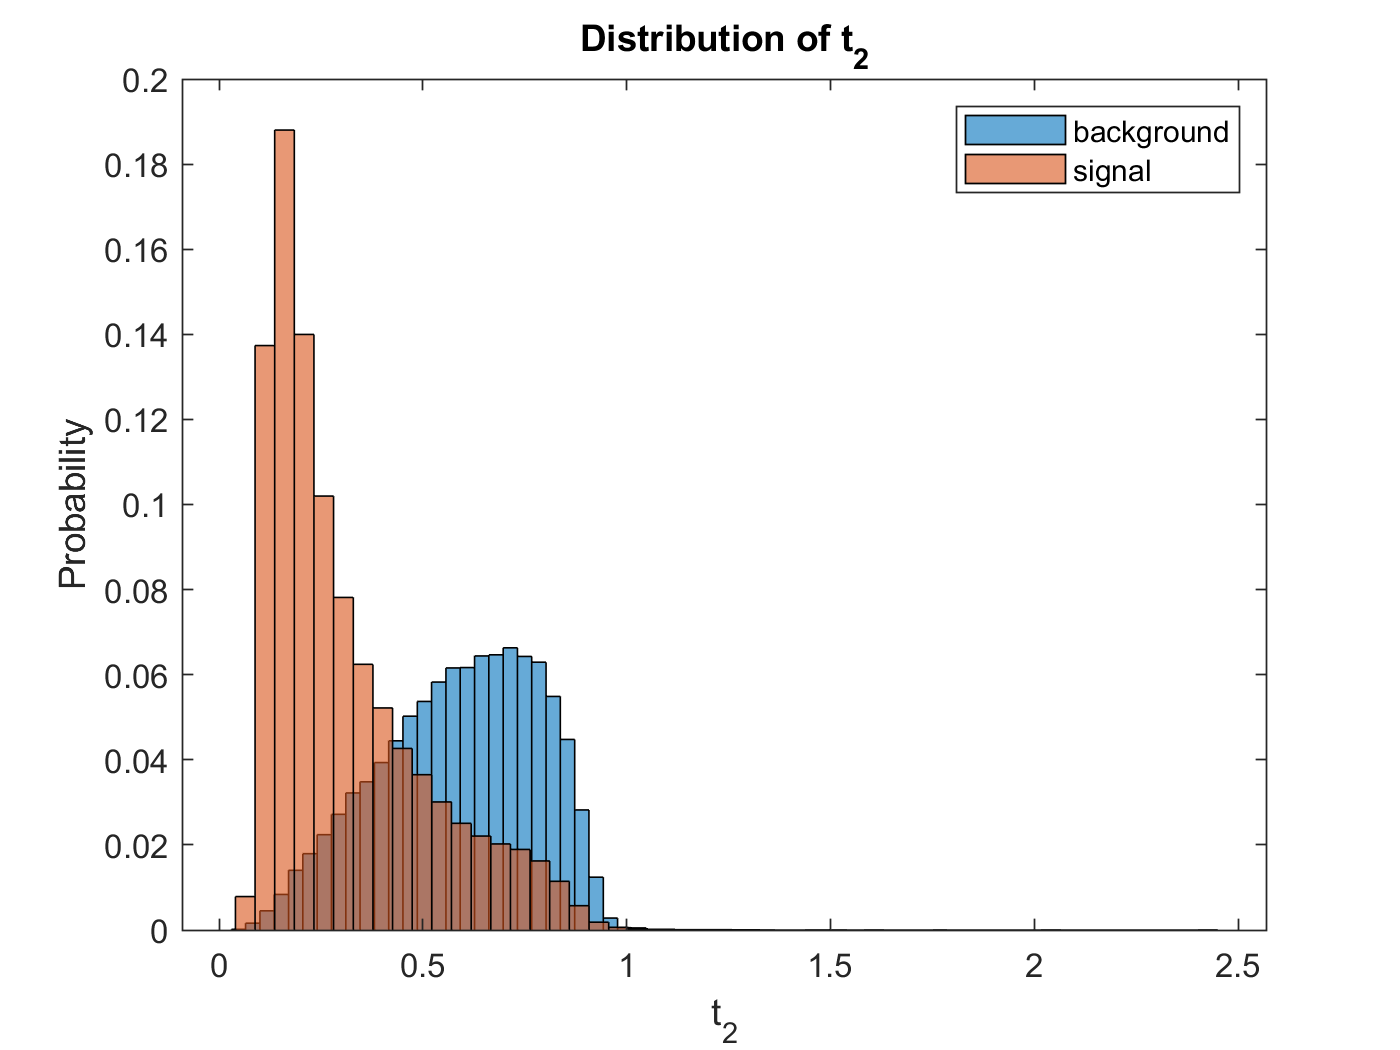

%plot t2
t2=background(10,:);
t2s=signal(10,:);

histogram(t2,50,'Normalization','probability')
hold on
histogram(t2s,50,'Normalization','probability')
legend('background','signal')
title('Distribution of t_{2}')
ylabel('Probability')
xlabel('t_{2}')
hold off

The plot shows to very different shapes and mean of signal and background. Therefore I would perform cuts to optimize the expected significance. I will cut anything above 0.2 as everything above is mostly backgorund data, and I can retain as much signal data as possible 

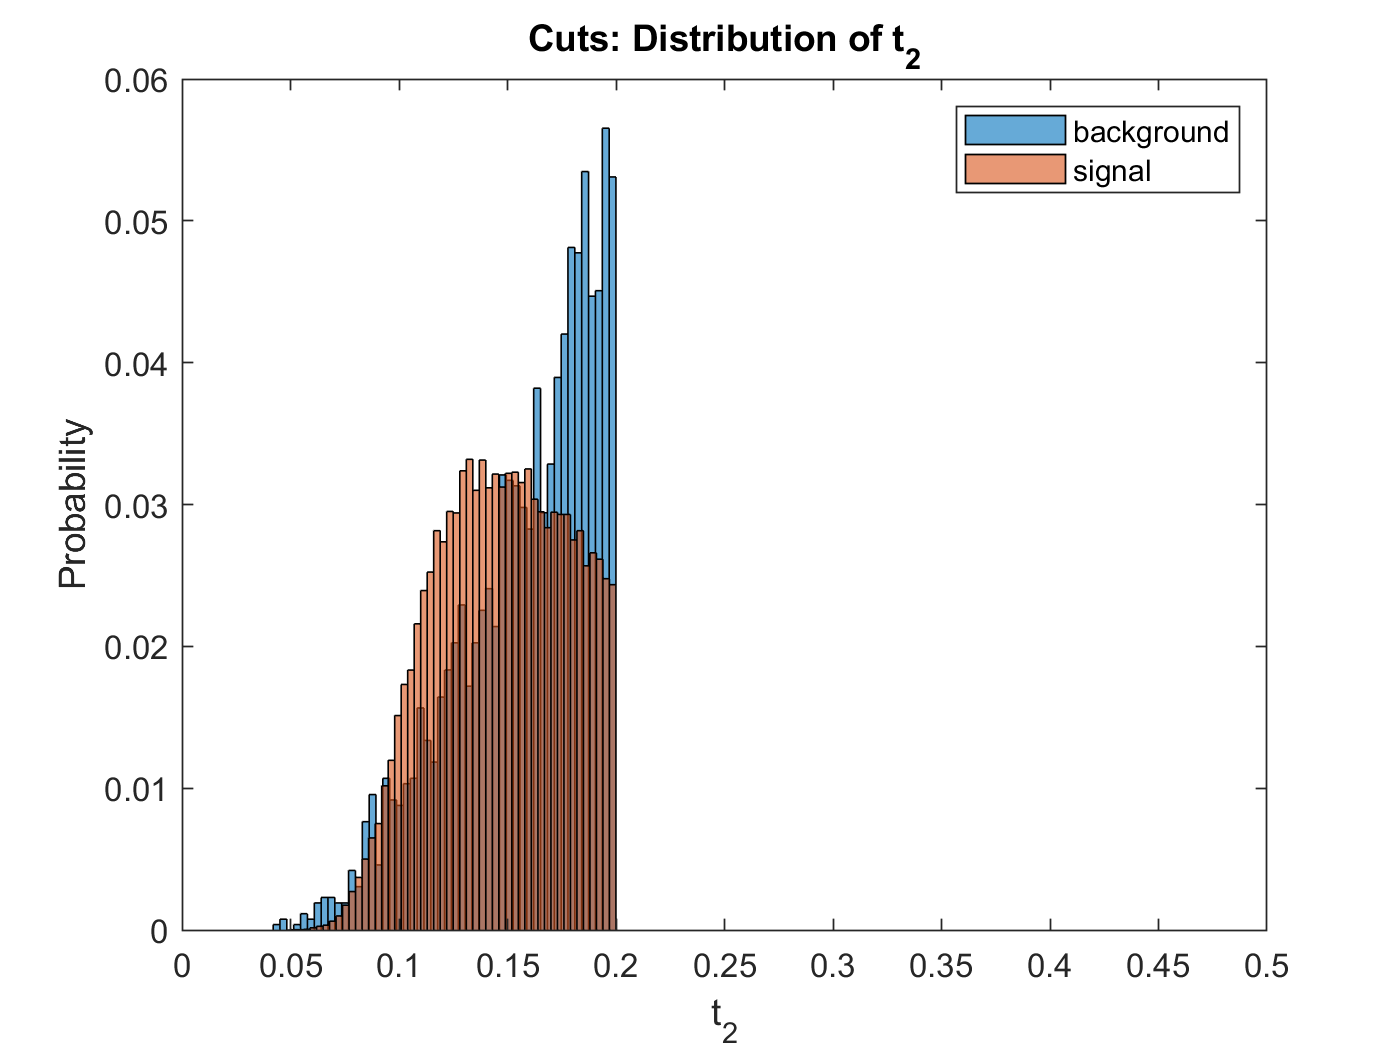

%cut: 0.2>t2
t2(t2>0.2)=[]; %greater than
N_t2=length(t2); %background, qcd

t2s(t2s>0.2)=[]; %greater than
N_t2s=length(t2s);%higgs, signal

M=N_t2s/sqrt(N_t2);
histogram(t2,50,'Normalization','probability');
hold on
histogram(t2s,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of t_{2}')
ylabel('Probability')
xlabel('t_{2}')
xlim([0 0.5])
hold off

The plot of the cut, is similar enough were I would not perform anymore cuts to optimize the expected significance. 

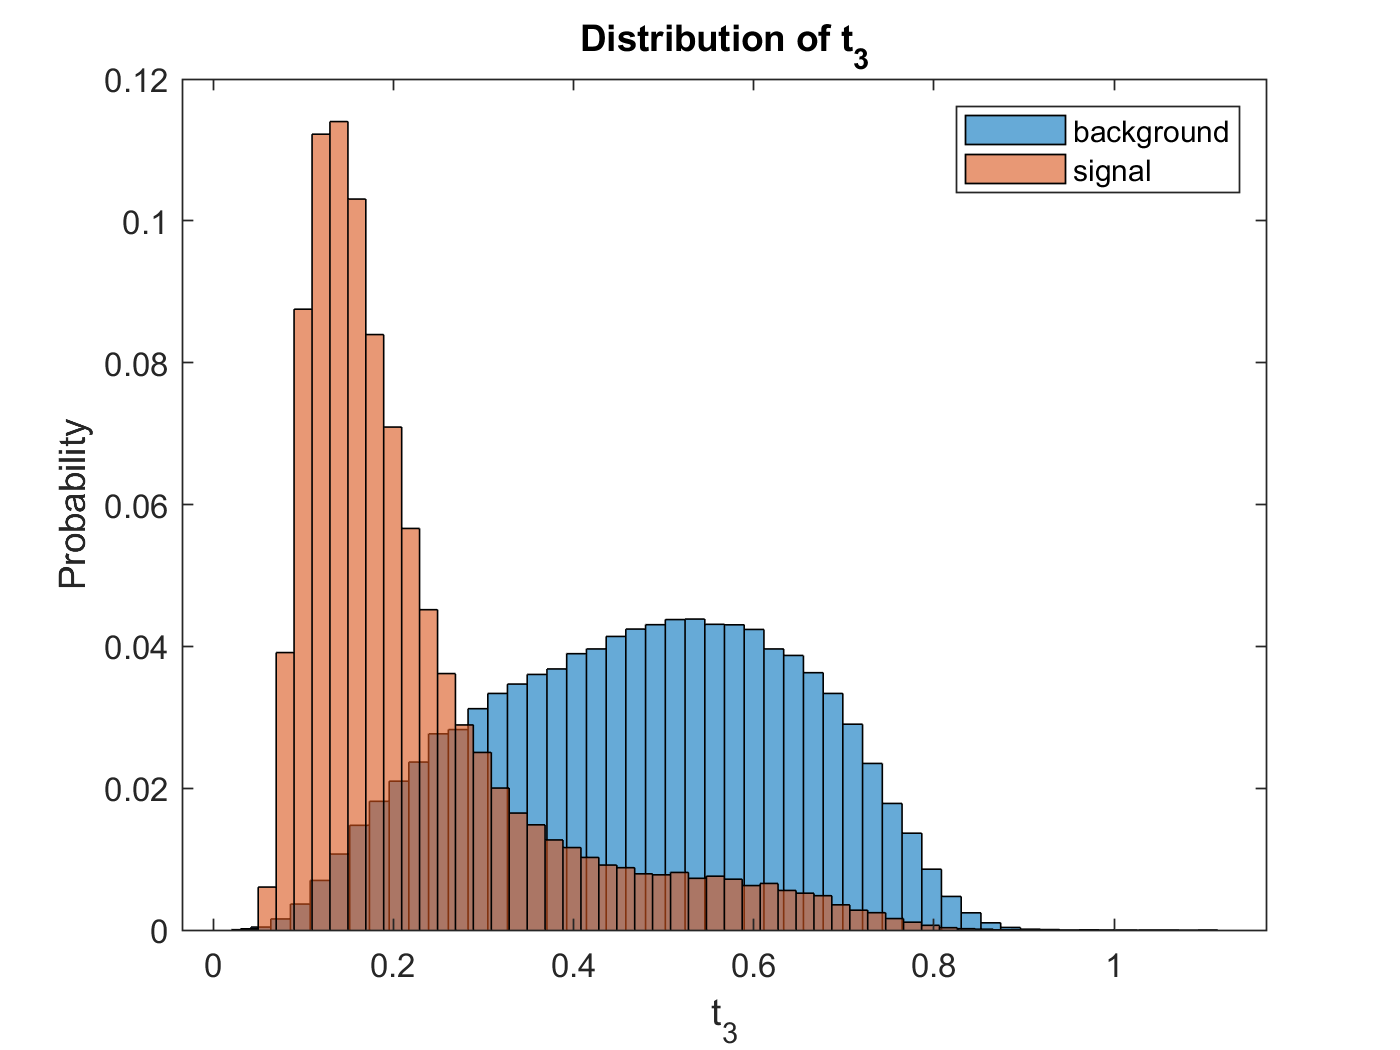

%plot t3
t3=background(11,:);
t3s=signal(11,:);

histogram(t3,50,'Normalization','probability')
hold on
histogram(t3s,50,'Normalization','probability')
legend('background','signal')
title('Distribution of t_{3}')
ylabel('Probability')
xlabel('t_{3}')
hold off

The plot shows to very different shapes and mean of signal and background. Therefore I would perform cuts to optimize the expected significance. I will cut anything about 0.2, as most of it is the background, that is cleary effecting the signal. 

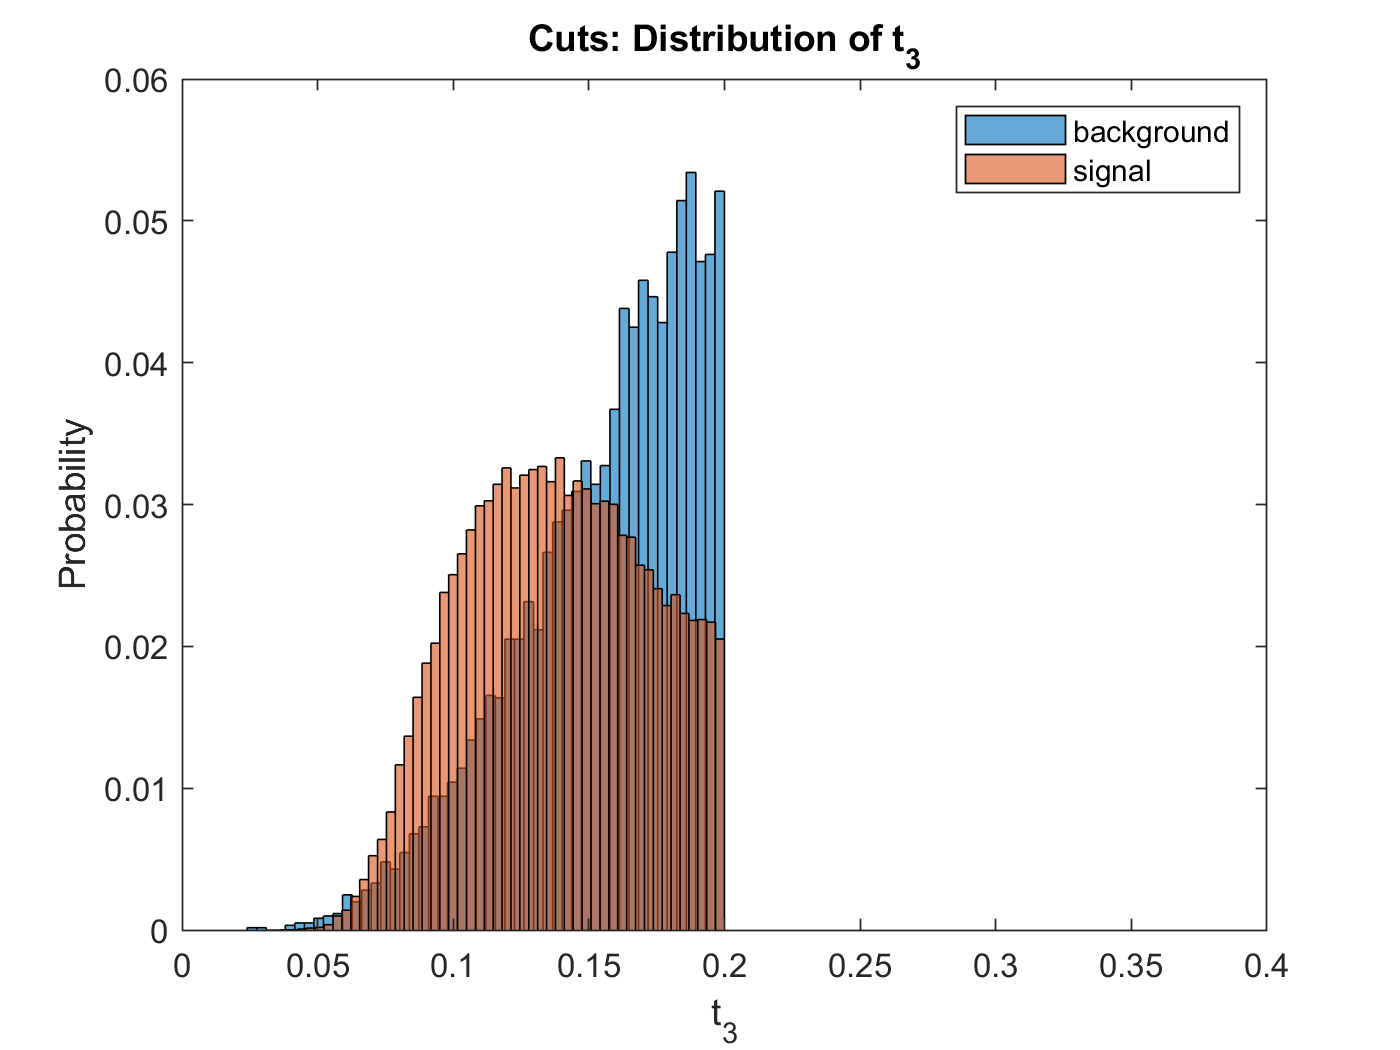

%cut: 0.2>t3
t3(t3>0.2)=[]; %greater than
N_t3=length(t3); %background, qcd

t3s(t3s>0.2)=[]; %greater than
N_t3s=length(t3s);%higgs, signal

M=N_t3s/sqrt(N_t3);
histogram(t3,50,'Normalization','probability');
hold on
histogram(t3s,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of t_{3}')
ylabel('Probability')
xlabel('t_{3}')
xlim([0 0.4])
hold off

The plot of the cut, is similar enough were I would not perform anymore cuts to optimize the expected significance. 

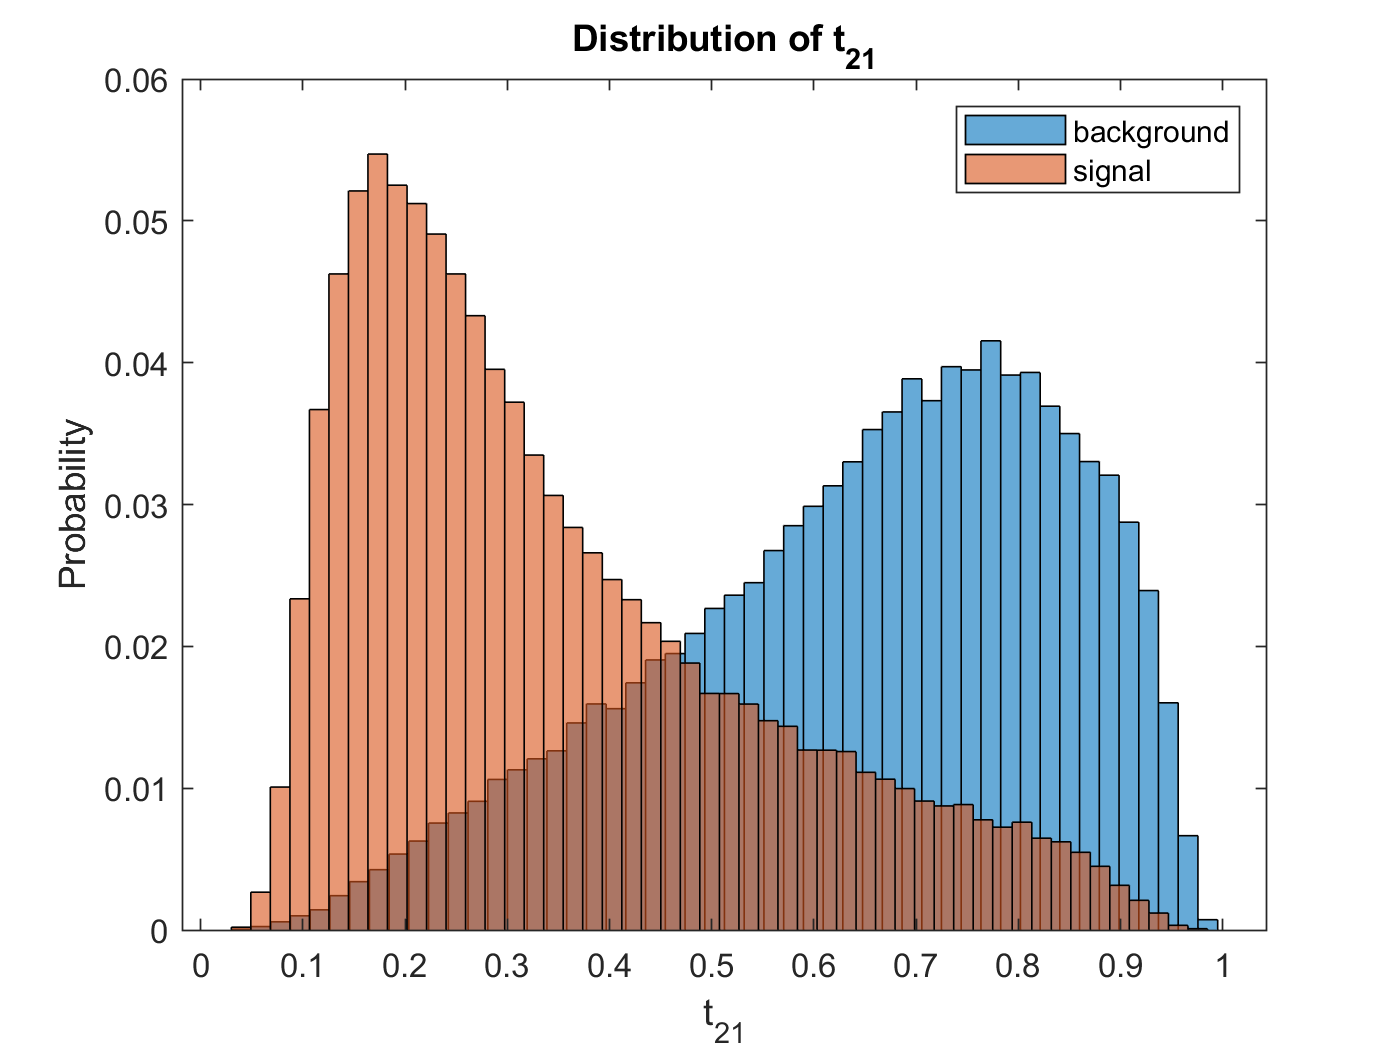

%plot t21
t21=background(12,:);
t21s=signal(12,:);

histogram(t21,50,'Normalization','probability')
hold on
histogram(t21s,50,'Normalization','probability')
legend('background','signal')
title('Distribution of t_{21}')
ylabel('Probability')
xlabel('t_{21}')
hold off

The plot shows to very different shapes and mean of signal and background. Therefore I would perform cuts to optimize the expected significance. I will cut anything above 0.2 as it is mostly the background data. I also would like to stay consitent with the last 2 cuts of t2 and t3 

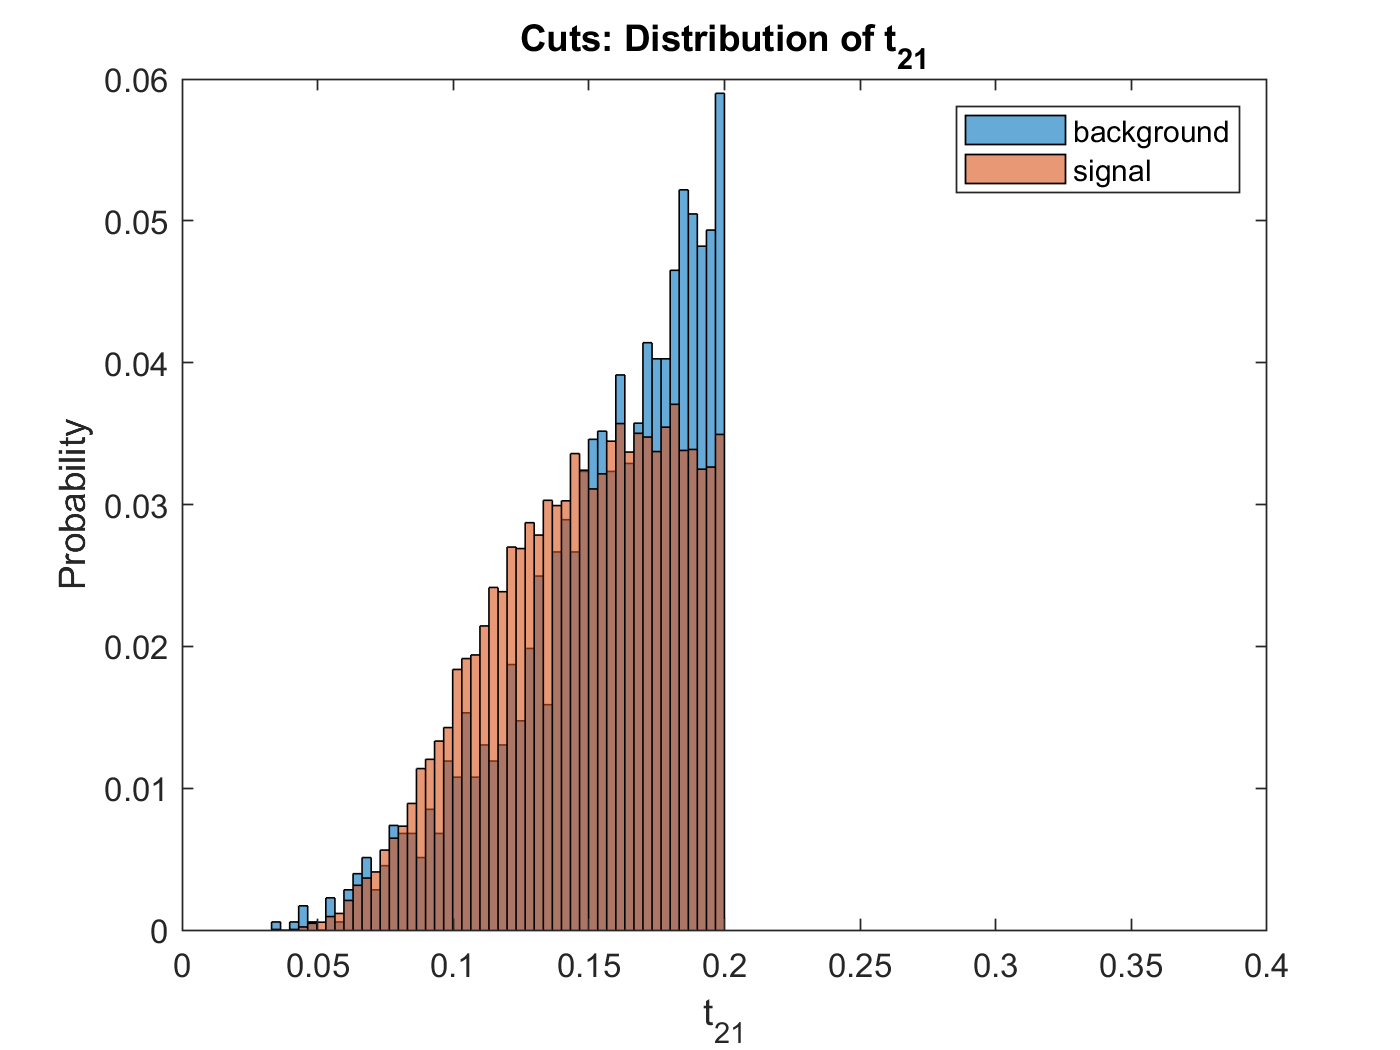

%cut: 0.2>t21
t21(t21>0.2)=[]; %greater than
N_t21=length(t21); %background, qcd

t21s(t21s>0.2)=[]; %greater than
N_t21s=length(t21s);%higgs, signal

M=N_t21s/sqrt(N_t21);
histogram(t21,50,'Normalization','probability');
hold on
histogram(t21s,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of t_{21}')
ylabel('Probability')
xlabel('t_{21}')
xlim([0 0.4])
hold off

The plot of the cut, is similar enough were I would not perform anymore cuts to optimize the expected significance. 

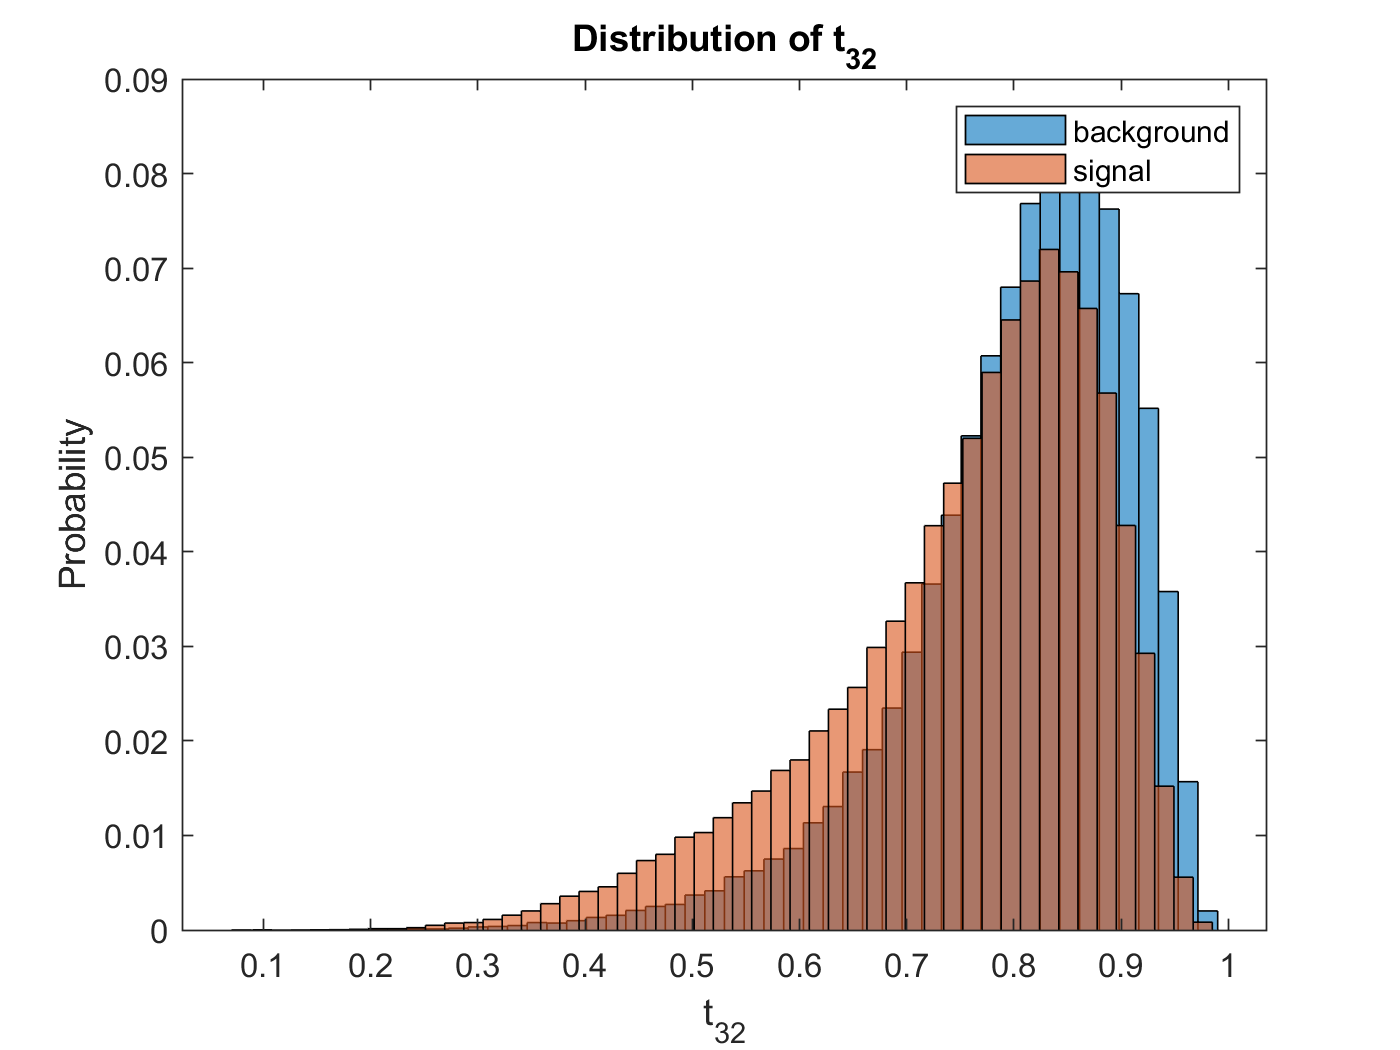

%plot t32, 
t32=background(13,:);
t32s=signal(13,:);

histogram(t32,50,'Normalization','probability')
hold on
histogram(t32s,50,'Normalization','probability')
legend('background','signal')
title('Distribution of t_{32}')
ylabel('Probability')
xlabel('t_{32}')
hold off

The plot is similar enough were I would not perform cuts to optimize the expected significance. 

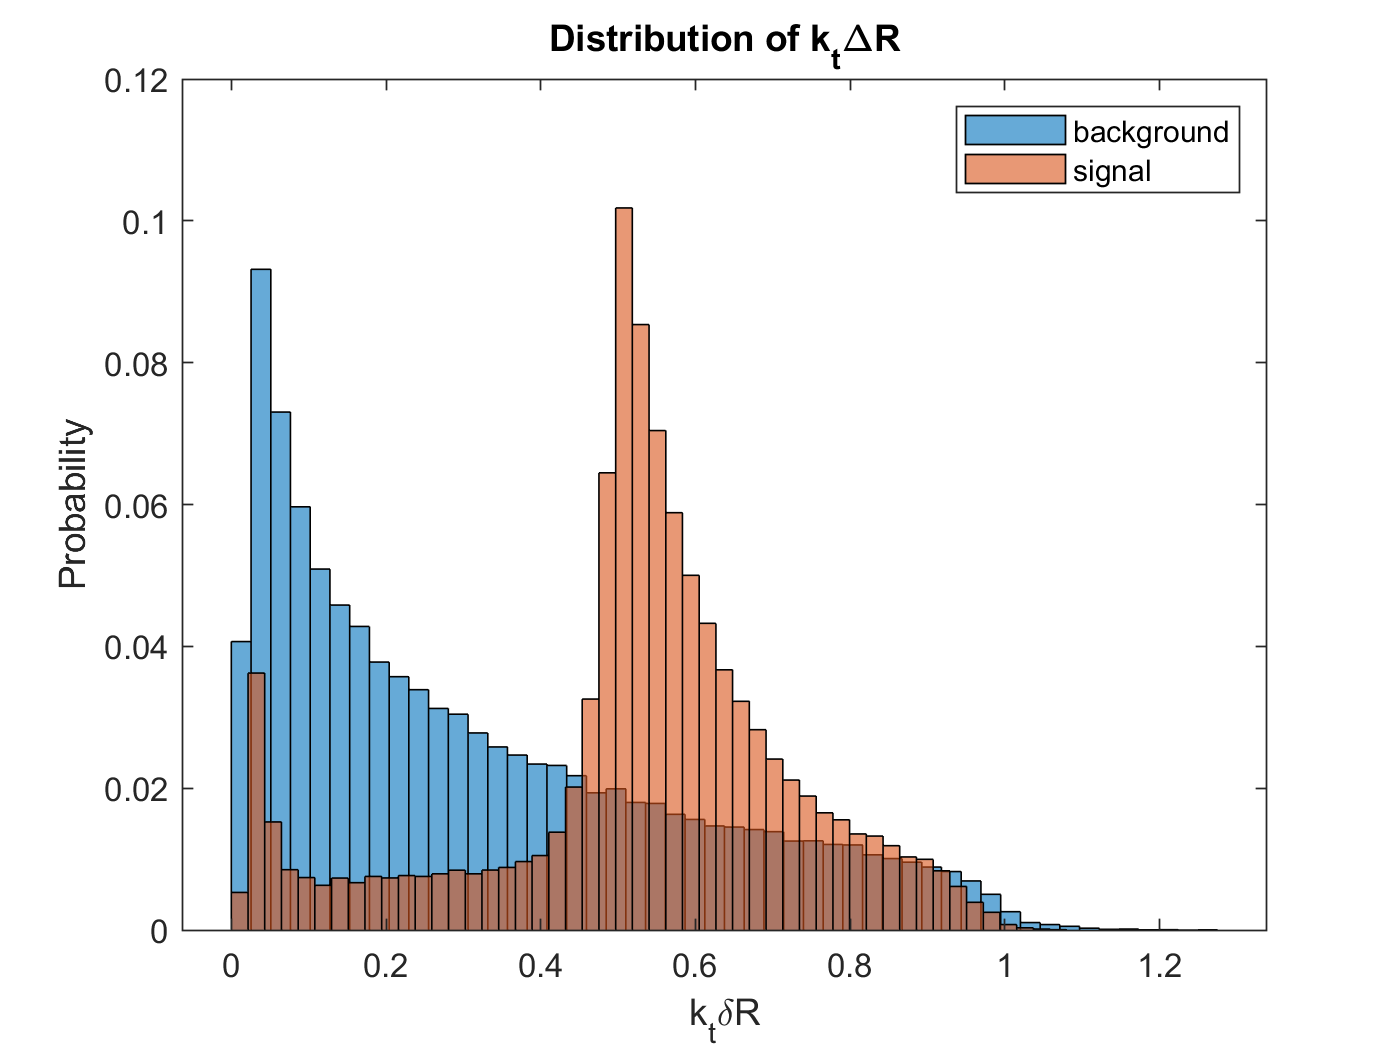

%ktdeltar plt
kt=background(14,:);
kts=signal(14,:);

histogram(kt,50,'Normalization','probability')
hold on
histogram(kts,50, 'Normalization','probability')
legend('background','signal')
title('Distribution of k_t\DeltaR')
ylabel('Probability')
xlabel('k_{t}\deltaR')
hold off

I will cut this so that I can optimze the expected significance, by getting rid of most of the background data and keeping as much of  the signal data as possile. I will cut anything below 0.4 and above 0.6, seeing as the signal spies around 0.5.

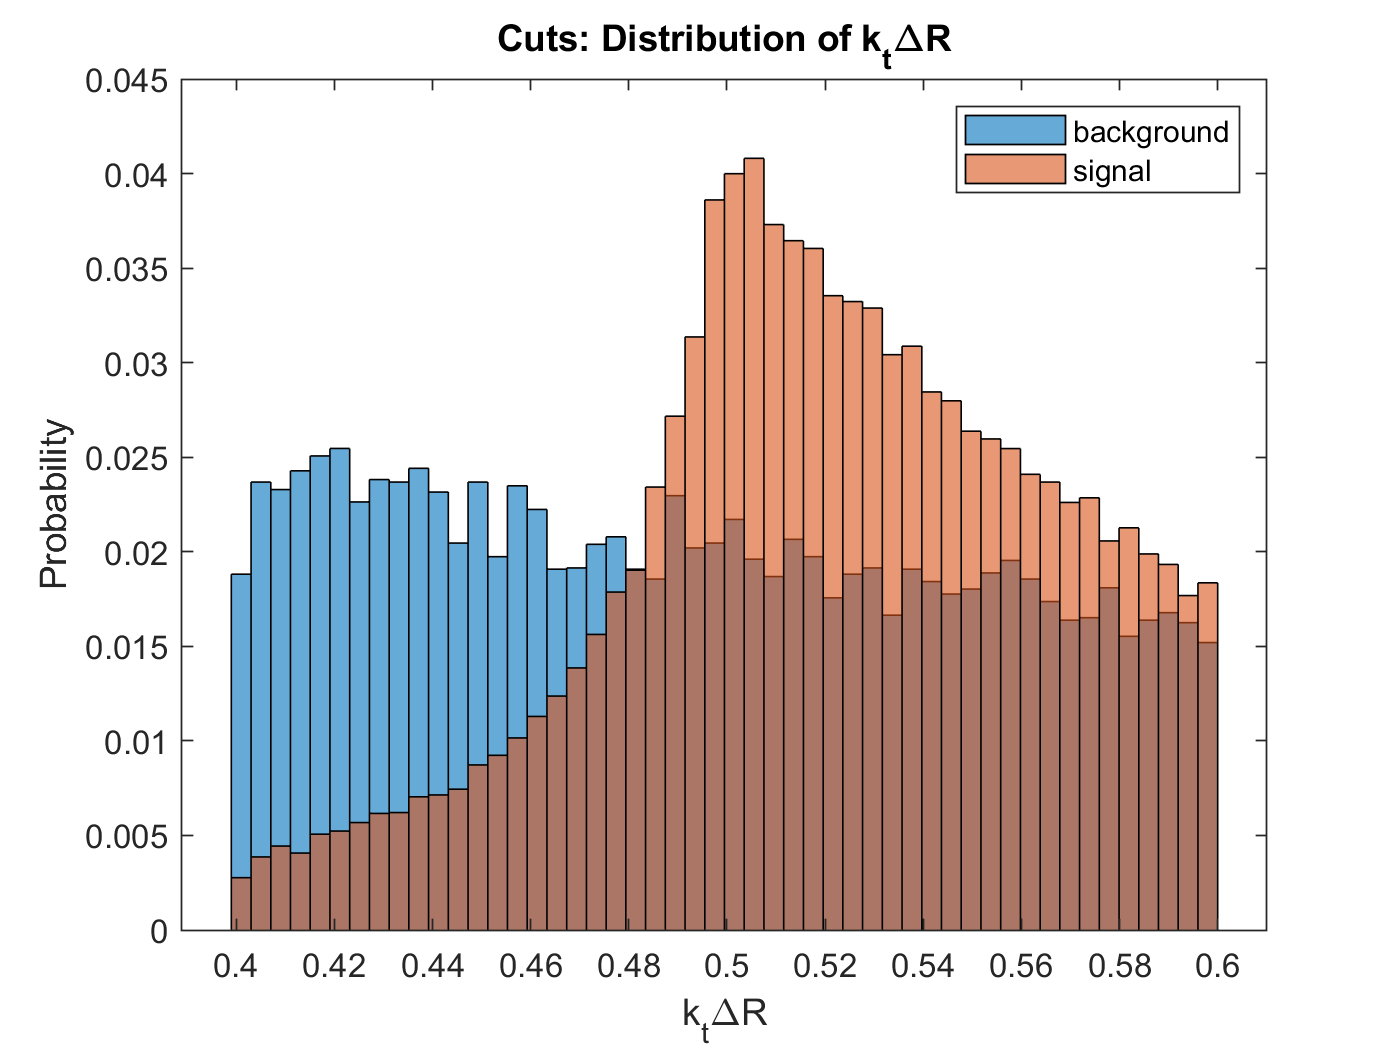

%cut: 0.4<kt<0.6
kt(kt<=0.4)=[]; %less than
kt(kt>0.6)=[]; %greater than
N_kt=length(kt); %background, qcd

kts(kts<=0.4)=[]; %less than
kts(kts>0.6)=[]; %greater than
N_kts=length(kts);%higgs, signal

M=N_kts/sqrt(N_kt);
histogram(kt,50,'Normalization','probability');
hold on
histogram(kts,50,'Normalization','probability');
legend('background','signal')
title('Cuts: Distribution of k_t\DeltaR')
ylabel('Probability')
xlabel('k_t\DeltaR')
hold off